data = readtable('data_reduced.csv');
% add corresponding row to general feature arrayj
%fcareful!irst row is the rank of features
PER = readtable('rf_permutation_partitions.csv');

lables= data.Properties.VariableNames

lables = 1×47 cell array
    {'Matrix_family'}    {'Matrix_crystallinity'}    {'Matrix_topology'}    {'Matrix_SCB'}    {'Matrix_LCB'}    {'Matrix_viscosity'}    {'Contaminant_family'}    {'Contaminant_crystallinity'}    {'Contaminant_topology'}    {'Contaminant_SCB'}    {'Contaminant_LCB'}    {'Contaminant_viscosity'}    {'WeightImpurity'}    {'matrixE'}    {'matrixSTRENGTH'}    {'matrixStrainbreak'}    {'matrixImpact'}    {'impurityE'}    {'impuritySTRENGTH'}    {'impurityStrainbreak'}    {'impurityImpact'}    {'matrixXc'}    {'impurityXc'}    {'blendE'}    {'blendSTRENGTH'}    {'blendStrainbreak'}    {'blendImpact'}    {'MajorityPolymer_HDPE1'}    {'MajorityPolymer_LDPE1'}    {'MajorityPolymer_LLDPE1'}    {'MajorityPolymer_PA1'}    {'MajorityPolymer_PET1'}    {'MajorityPolymer_PP1'}    {'MajorityPolymer_PP2'}    {'MajorityPolymer_PP3'}    {'MajorityPolymer_PS1'}    {'MajorityPolymer_PS2'}    {'MinorityPolymer_HDPE1'}    {'MinorityPolymer_LDPE1'}    {'MinorityPolymer_LLDPE1'}    {'Min

lables = cell2table(lables);
lablesS = lables(1, 1:13);
lablesS2 = lables(1,28:end);
lablesE= [lablesS, lables(1,14), lables(1,18), lables(1,22:23), lablesS2];
lablesYE= lables(1,24);

12 features + %impurity

col 14 matrix E, 18 impurity E

col 22, 23 Matrix/imp XC

col 24 blendE

col 28 start of 1H (Majority and min polymers)

E =  table2array(data(:,[1 2 3 4 5 6 7 8 9 10 11 12 13 14 18 22 23 24 28 29 30 31 40 41 42 43 44 45 46 47  ]))

E = 1.0e+03 *

         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020    0.0010         0         0    0.0050    0.0005    0.1924    0.9529    0.0327    0.0651    0.4624         0    0.0010         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020    0.0010         0         0    0.0050    0.0002    0.1924    0.9529    0.0327    0.0651    0.2918         0    0.0010         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020    0.0010         0         0    0.0050    0.0001    0.1924    0.9529    0.0327    0.0651    0.2380         0    0.0010         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020  

%separate and normalize so range between [0,1] but NOT standarize 
Xe= [E(:,1:17), E(:,19:end)];
Ye = E(:,18)./max(E(:,18)); 
%only normalize the continuous columns (%impurity already ranges 0,1)
cols_continuous_norm = Xe(:,14:17) ./ max(Xe(:,14:17))

cols_continuous_norm =     0.0601    0.2976    0.4860    0.9677
    0.0601    0.2976    0.4860    0.9677
    0.0601    0.2976    0.4860    0.9677
    0.0601    0.2976    0.4860    0.9677
    0.0601    0.2976    0.4860    0.9677
    0.0601    0.2976    0.4860    0.9677
    0.0601         0    0.4860         0
    0.0601    0.0355    0.4860    0.4281
    0.0601    0.0355    0.4860    0.4281
    0.0601    0.0355    0.4860    0.4281


Xe(:,14:17)= cols_continuous_norm;

#### Getting familiriazed with NCA implementation (add in Appendix?)

% default l= 1/n
nca = fsrnca(Xe, Ye,'Verbose',2)


 o Solver = LBFGS, HessianHistorySize = 15, LineSearchMethod = weakwolfe

|====================================================================================================|
|   ITER   |   FUN VALUE   |  NORM GRAD  |  NORM STEP  |  CURV  |    GAMMA    |    ALPHA    | ACCEPT |
|====================================================================================================|
|        0 |  1.805313e-01 |   7.983e-03 |   0.000e+00 |        |   7.516e+01 |   0.000e+00 |   YES  |
|        1 |  1.395318e-01 |   1.772e-02 |   2.208e+00 |    OK  |   4.044e+01 |   1.000e+00 |   YES  |
|        2 |  1.339777e-01 |   1.053e-02 |   2.236e+00 |    OK  |   3.232e+01 |   1.000e+00 |   YES  |
|        3 |  1.272269e-01 |   6.884e-03 |   5.519e-01 |    OK  |   4.648e+01 |   1.000e+00 |   YES  |
|        4 |  1.234164e-01 |   1.086e-02 |   7.635e-01 |    OK  |   2.369e+01 |   5.000e-01 |   YES  |
|        5 |  1.213879e-01 |   3.126e-03 |   3.941e-01 |    OK  |   1.749e+01 |   1.000e+00 |   YES  

nca =   FeatureSelectionNCARegression
          NumObservations: 328
          ModelParameters: [1×1 struct]
                   Lambda: 0.0030
                FitMethod: 'exact'
                   Solver: 'lbfgs'
        GradientTolerance: 1.0000e-06
           IterationLimit: 1000
                PassLimit: 5
      InitialLearningRate: []
                  Verbose: 2
    InitialFeatureWeights: [29×1 double]
           FeatureWeights: [29×1 double]
                  FitInfo: [1×1 struct]
                       Mu: []
                    Sigma: []
                        X: [328×29 double]
                        Y: [328×1 double]
                        W: [328×1 double]


  Properties, Methods


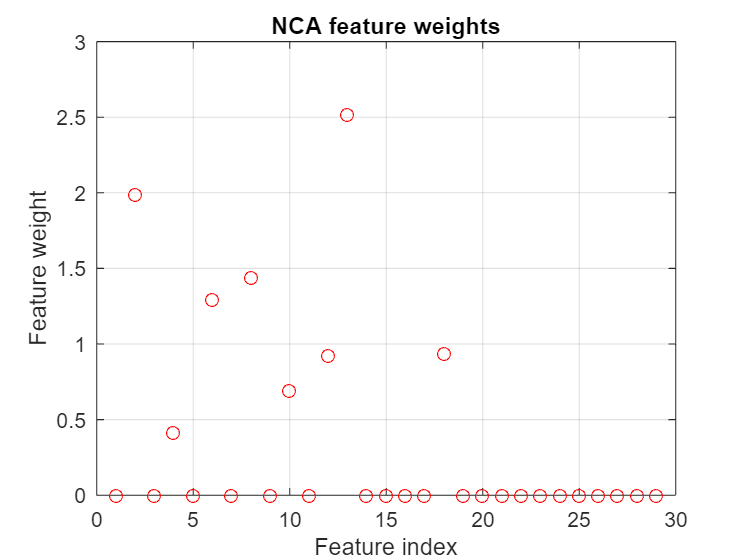

figure()
plot(nca.FeatureWeights,'ro')
grid on
xlabel('Feature index')
ylabel('Feature weight')
title('NCA feature weights')


figure
fitted = predict(nca, Xe)

fitted =     0.1609
    0.0876
    0.0772
    0.0735
    0.0722
    0.0716
    0.0714
    0.0732
    0.0700
    0.0702


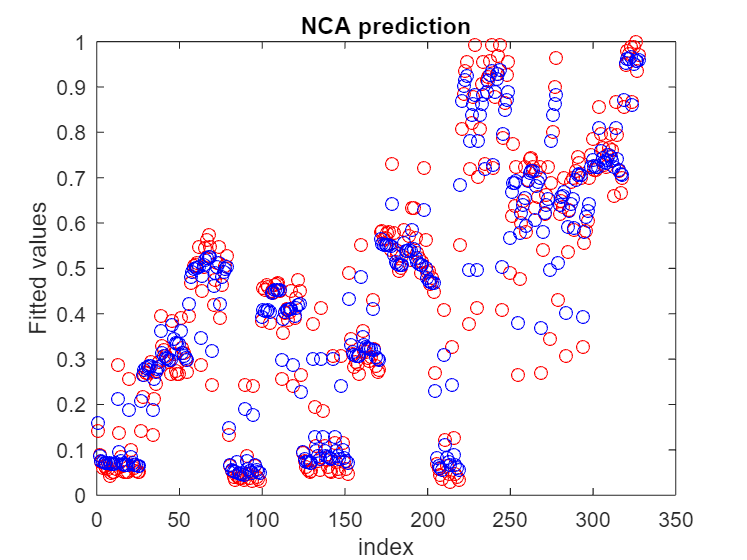

plot(Ye,'ro')
hold on
plot(fitted,'bo')
xlabel('index')
ylabel('Fitted values')
title('NCA prediction')

regression is too strong? 

try different loss functions and test against random weights ->not big impact with L =1/n

% check the other funcion
nca = fsrnca(Xe, Ye, 'Verbose',2)


 o Solver = LBFGS, HessianHistorySize = 15, LineSearchMethod = weakwolfe

|====================================================================================================|
|   ITER   |   FUN VALUE   |  NORM GRAD  |  NORM STEP  |  CURV  |    GAMMA    |    ALPHA    | ACCEPT |
|====================================================================================================|
|        0 |  1.805313e-01 |   7.983e-03 |   0.000e+00 |        |   7.516e+01 |   0.000e+00 |   YES  |
|        1 |  1.395318e-01 |   1.772e-02 |   2.208e+00 |    OK  |   4.044e+01 |   1.000e+00 |   YES  |
|        2 |  1.339777e-01 |   1.053e-02 |   2.236e+00 |    OK  |   3.232e+01 |   1.000e+00 |   YES  |
|        3 |  1.272269e-01 |   6.884e-03 |   5.519e-01 |    OK  |   4.648e+01 |   1.000e+00 |   YES  |
|        4 |  1.234164e-01 |   1.086e-02 |   7.635e-01 |    OK  |   2.369e+01 |   5.000e-01 |   YES  |
|        5 |  1.213879e-01 |   3.126e-03 |   3.941e-01 |    OK  |   1.749e+01 |   1.000e+00 |   YES  

nca =   FeatureSelectionNCARegression
          NumObservations: 328
          ModelParameters: [1×1 struct]
                   Lambda: 0.0030
                FitMethod: 'exact'
                   Solver: 'lbfgs'
        GradientTolerance: 1.0000e-06
           IterationLimit: 1000
                PassLimit: 5
      InitialLearningRate: []
                  Verbose: 2
    InitialFeatureWeights: [29×1 double]
           FeatureWeights: [29×1 double]
                  FitInfo: [1×1 struct]
                       Mu: []
                    Sigma: []
                        X: [328×29 double]
                        Y: [328×1 double]
                        W: [328×1 double]


  Properties, Methods



% rand_weights= rand(size(Xe,2),1)
% default regularization
% nca_rand= fsrnca(Xe, Ye, 'InitialFeatureWeights',rand_weights,'Verbose',2)

% from mad= 0.0288; mse= 0.0015just squared, take absolute error 

% lossNCAMSERAND = loss(nca_rand,Xtest,Ytest,'LossFunction','mse');  
% 
% lossNCAMADRAND = loss(nca_rand,Xtest,Ytest,'LossFunction','mad');  

%just the sqrt, keep MAD
lossNCAMSE = loss(nca,Xe,Ye,'LossFunction','mse')  

lossNCAMSE = 0.0015

lossNCAMAD = loss(nca,Xe,Ye,'LossFunction','mad')  

lossNCAMAD = 0.0293

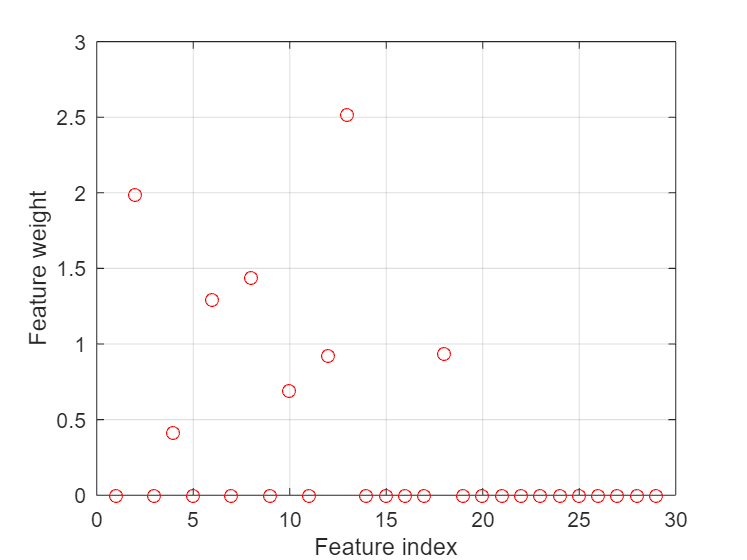

figure()
plot(nca.FeatureWeights,'ro')
grid on
xlabel('Feature index')
ylabel('Feature weight')

nca_none = fsrnca(Xe, Ye,'FitMethod', 'none', 'Verbose',2)

nca_none =   FeatureSelectionNCARegression
          NumObservations: 328
          ModelParameters: [1×1 struct]
                   Lambda: 0.0030
                FitMethod: 'none'
                   Solver: 'lbfgs'
        GradientTolerance: 1.0000e-06
           IterationLimit: 1000
                PassLimit: 5
      InitialLearningRate: []
                  Verbose: 2
    InitialFeatureWeights: [29×1 double]
           FeatureWeights: [29×1 double]
                  FitInfo: []
                       Mu: []
                    Sigma: []
                        X: [328×29 double]
                        Y: [328×1 double]
                        W: [328×1 double]


  Properties, Methods


loss_none = loss(nca_none,Xe,Ye,'LossFunction','mad') 

loss_none = 0.0531


nca_avg= fsrnca(Xe, Ye, 'FitMethod', 'average','LossFunction','mad')

nca_avg =   FeatureSelectionNCARegression
          NumObservations: 328
          ModelParameters: [1×1 struct]
                   Lambda: 0.0030
                FitMethod: 'average'
                   Solver: 'lbfgs'
        GradientTolerance: 1.0000e-06
           IterationLimit: 1000
                PassLimit: 5
      InitialLearningRate: []
                  Verbose: 0
    InitialFeatureWeights: [29×1 double]
           FeatureWeights: [29×10 double]
                  FitInfo: [10×1 struct]
                       Mu: []
                    Sigma: []
                        X: [328×29 double]
                        Y: [328×1 double]
                        W: [328×1 double]


  Properties, Methods


loss_avg = loss(nca_avg,Xe,Ye,'LossFunction','mad') 

loss_avg = 0.0676

(LBFGS)EXACT MAD: 0.0303    NONE :0.053      AVG : 0.0681

(SGD) exact : 0.0291, minibatch_lbfgs: 0.0293

 nca_sgd = fsrnca(Xe, Ye,'FitMethod', 'exact','solver','lbfgs','Verbose',2)


 o Solver = LBFGS, HessianHistorySize = 15, LineSearchMethod = weakwolfe

|====================================================================================================|
|   ITER   |   FUN VALUE   |  NORM GRAD  |  NORM STEP  |  CURV  |    GAMMA    |    ALPHA    | ACCEPT |
|====================================================================================================|
|        0 |  1.805313e-01 |   7.983e-03 |   0.000e+00 |        |   7.516e+01 |   0.000e+00 |   YES  |
|        1 |  1.395318e-01 |   1.772e-02 |   2.208e+00 |    OK  |   4.044e+01 |   1.000e+00 |   YES  |
|        2 |  1.339777e-01 |   1.053e-02 |   2.236e+00 |    OK  |   3.232e+01 |   1.000e+00 |   YES  |
|        3 |  1.272269e-01 |   6.884e-03 |   5.519e-01 |    OK  |   4.648e+01 |   1.000e+00 |   YES  |
|        4 |  1.234164e-01 |   1.086e-02 |   7.635e-01 |    OK  |   2.369e+01 |   5.000e-01 |   YES  |
|        5 |  1.213879e-01 |   3.126e-03 |   3.941e-01 |    OK  |   1.749e+01 |   1.000e+00 |   YES  

nca_sgd =   FeatureSelectionNCARegression
          NumObservations: 328
          ModelParameters: [1×1 struct]
                   Lambda: 0.0030
                FitMethod: 'exact'
                   Solver: 'lbfgs'
        GradientTolerance: 1.0000e-06
           IterationLimit: 1000
                PassLimit: 5
      InitialLearningRate: []
                  Verbose: 2
    InitialFeatureWeights: [29×1 double]
           FeatureWeights: [29×1 double]
                  FitInfo: [1×1 struct]
                       Mu: []
                    Sigma: []
                        X: [328×29 double]
                        Y: [328×1 double]
                        W: [328×1 double]


  Properties, Methods


 loss_sgd = loss(nca_sgd,Xe,Ye,'LossFunction','mad') 

loss_sgd = 0.0293


nca_minibatch = fsrnca(Xe, Ye,'FitMethod', 'exact','solver','minibatch-lbfgs','Verbose',2)


 o Tuning initial learning rate: NumTuningIterations = 20, TuningSubsetSize = 100

|===============================================|
|    TUNING    | TUNING SUBSET |    LEARNING    |
|     ITER     |   FUN VALUE   |      RATE      |
|===============================================|
|            1 |  1.681935e-01 |   2.000000e-01 |
|            2 |  1.665878e-01 |   4.000000e-01 |
|            3 |  1.635097e-01 |   8.000000e-01 |
|            4 |  1.578734e-01 |   1.600000e+00 |
|            5 |  1.482788e-01 |   3.200000e+00 |
|            6 |  1.351271e-01 |   6.400000e+00 |
|            7 |  1.230452e-01 |   1.280000e+01 |
|            8 |  1.170551e-01 |   2.560000e+01 |
|            9 |  1.141443e-01 |   5.120000e+01 |
|           10 |  1.141443e-01 |   5.120000e+01 |
|           11 |  1.141443e-01 |   5.120000e+01 |
|           12 |  1.141443e-01 |   5.120000e+01 |
|           13 |  1.141443e-01 |   5.120000e+01 |
|           14 |  1.141443e-01 |   5.120000e+01 |
|           15 |

nca_minibatch =   FeatureSelectionNCARegression
          NumObservations: 328
          ModelParameters: [1×1 struct]
                   Lambda: 0.0030
                FitMethod: 'exact'
                   Solver: 'minibatch-lbfgs'
        GradientTolerance: 1.0000e-06
           IterationLimit: 1000
                PassLimit: 5
      InitialLearningRate: []
                  Verbose: 2
    InitialFeatureWeights: [29×1 double]
           FeatureWeights: [29×1 double]
                  FitInfo: [1×1 struct]
                       Mu: []
                    Sigma: []
                        X: [328×29 double]
                        Y: [328×1 double]
                        W: [328×1 double]


  Properties, Methods


loss_mb = loss(nca_minibatch,Xe,Ye,'LossFunction','mad')

loss_mb = 0.0368

% 'lbfgs' | 'sgd' | 'minibatch-lbfgs'

% not stratisfied
c = cvpartition(size(Xe, 1),'Holdout',0.25)

c = Hold-out cross validation partition
   NumObservations: 328
       NumTestSets: 1
         TrainSize: 246
          TestSize: 82

idxTrain = training(c)

idxTrain = 328×1 logical array
   1
   0
   1
   1
   1
   1
   0
   1
   0
   1


x_train = Xe(idxTrain,:);
y_train = Ye(idxTrain,1)

y_train =     0.1434
    0.0738
    0.0621
    0.0655
    0.0616
    0.0431
    0.0522
    0.0530
    0.0597
    0.2874


idxNew = test(c)

idxNew = 328×1 logical array
   0
   1
   0
   0
   0
   0
   1
   0
   1
   0


x_test = Xe(idxNew,:);
y_test = Ye(idxNew,1);

nca_test = fsrnca(x_train,y_train ,'FitMethod', 'exact','solver','sgd','Verbose',2)


 o Tuning initial learning rate: NumTuningIterations = 20, TuningSubsetSize = 100

|===============================================|
|    TUNING    | TUNING SUBSET |    LEARNING    |
|     ITER     |   FUN VALUE   |      RATE      |
|===============================================|
|            1 |  2.025822e-01 |   2.000000e-01 |
|            2 |  1.999421e-01 |   4.000000e-01 |
|            3 |  1.949905e-01 |   8.000000e-01 |
|            4 |  1.861879e-01 |   1.600000e+00 |
|            5 |  1.724306e-01 |   3.200000e+00 |
|            6 |  1.557282e-01 |   6.400000e+00 |
|            7 |  1.408715e-01 |   1.280000e+01 |
|            8 |  1.343148e-01 |   2.560000e+01 |
|            9 |  1.335606e-01 |   5.120000e+01 |
|           10 |  1.335606e-01 |   5.120000e+01 |
|           11 |  1.335606e-01 |   5.120000e+01 |
|           12 |  1.335606e-01 |   5.120000e+01 |
|           13 |  1.325059e-01 |   2.560000e+01 |
|           14 |  1.325059e-01 |   2.560000e+01 |
|           15 |

nca_test =   FeatureSelectionNCARegression
          NumObservations: 246
          ModelParameters: [1×1 struct]
                   Lambda: 0.0041
                FitMethod: 'exact'
                   Solver: 'sgd'
        GradientTolerance: 1.0000e-06
           IterationLimit: 10000
                PassLimit: 5
      InitialLearningRate: []
                  Verbose: 2
    InitialFeatureWeights: [29×1 double]
           FeatureWeights: [29×1 double]
                  FitInfo: [1×1 struct]
                       Mu: []
                    Sigma: []
                        X: [246×29 double]
                        Y: [246×1 double]
                        W: [246×1 double]


  Properties, Methods


loss_sgd = loss(nca_test,x_test,y_test,'LossFunction','mad')

loss_sgd = 0.0679

nca_test = fsrnca(x_train,y_train ,'FitMethod', 'exact','Verbose',2)


 o Solver = LBFGS, HessianHistorySize = 15, LineSearchMethod = weakwolfe

|====================================================================================================|
|   ITER   |   FUN VALUE   |  NORM GRAD  |  NORM STEP  |  CURV  |    GAMMA    |    ALPHA    | ACCEPT |
|====================================================================================================|
|        0 |  2.054179e-01 |   9.320e-03 |   0.000e+00 |        |   6.438e+01 |   0.000e+00 |   YES  |
|        1 |  1.561187e-01 |   3.105e-02 |   2.457e+00 |    OK  |   2.456e+01 |   1.000e+00 |   YES  |
|        2 |  1.404617e-01 |   1.229e-02 |   1.852e+00 |    OK  |   1.598e+01 |   1.000e+00 |   YES  |
|        3 |  1.371654e-01 |   9.453e-03 |   2.112e-01 |    OK  |   3.481e+01 |   1.000e+00 |   YES  |
|        4 |  1.340562e-01 |   1.543e-02 |   8.559e-01 |    OK  |   1.665e+01 |   1.000e+00 |   YES  |
|        5 |  1.318576e-01 |   5.394e-03 |   3.052e-01 |    OK  |   1.146e+01 |   1.000e+00 |   YES  

nca_test =   FeatureSelectionNCARegression
          NumObservations: 246
          ModelParameters: [1×1 struct]
                   Lambda: 0.0041
                FitMethod: 'exact'
                   Solver: 'lbfgs'
        GradientTolerance: 1.0000e-06
           IterationLimit: 1000
                PassLimit: 5
      InitialLearningRate: []
                  Verbose: 2
    InitialFeatureWeights: [29×1 double]
           FeatureWeights: [29×1 double]
                  FitInfo: [1×1 struct]
                       Mu: []
                    Sigma: []
                        X: [246×29 double]
                        Y: [246×1 double]
                        W: [246×1 double]


  Properties, Methods


loss_lbg = loss(nca_test,x_test,y_test,'LossFunction','mad')

loss_lbg = 0.0671

loss lbg = 0.0482, sgd =0.0505

cv        = cvpartition(Ye,'kfold',5);

numtestsets   = cv.NumTestSets;
lambdavalues  = linspace(0,1,20)/length(Ye); 
lossvalues    = zeros(length(lambdavalues),numtestsets);


n = 328; 
mape = @(y, yp) (abs(y - yp) ./y  )* 100/n

mape = function_handle with value:
    @(y,yp)(abs(y-yp)./y)*100/n



for i = 1:length(lambdavalues)                
    for k = 1:numtestsets
        
        % Extract the training set from the partition object
        Xtrain = Xe(cv.training(k),:);
        Ytrain = Ye(cv.training(k),:);
        
        % Extract the test set from the partition object
        Xtest = Xe(cv.test(k),:);
        Ytest = Ye(cv.test(k),:);
        
        % Train an nca model for classification using the training set
        ncaMdl = fsrnca(Xtrain,Ytrain,'FitMethod','exact','Standardize',true, ...
            'Solver','sgd','Lambda',lambdavalues(i) );
        
        % Compute the classification loss for the test set using the nca
        % model
        lossvalues(i,k) = loss(ncaMdl, Xtest, Ytest,'LossFunction','mad');   
   
    end                          
end

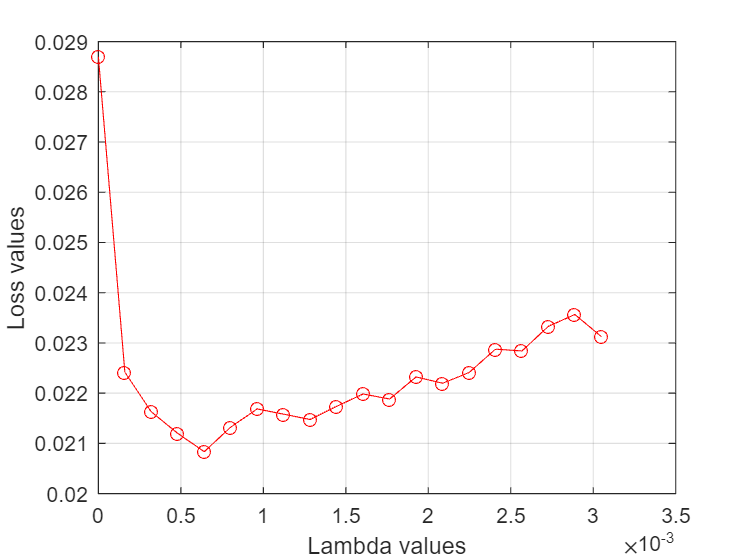

figure
plot(lambdavalues,mean(lossvalues,2),'ro-')
xlabel('Lambda values')
ylabel('Loss values')
grid on

lamba should be super small

same trend upwards in loss once l <0.00 (in scale 10 ^-3), find best lamdba 

[~,idx] = min(mean(lossvalues,2)); % Find the index
bestlambda = lambdavalues(idx) % Find the best lambda value

bestlambda = 6.4185e-04

ncaBest = fsrnca(Xtrain, Ytrain, 'FitMethod','exact','Verbose',1, ...
     'Solver','sgd','Lambda',bestlambda);


 o Tuning initial learning rate: NumTuningIterations = 20, TuningSubsetSize = 100

|===============================================|
|    TUNING    | TUNING SUBSET |    LEARNING    |
|     ITER     |   FUN VALUE   |      RATE      |
|===============================================|
|            1 |  1.152421e-01 |   2.000000e-01 |
|            2 |  1.147213e-01 |   4.000000e-01 |
|            3 |  1.136908e-01 |   8.000000e-01 |
|            4 |  1.116552e-01 |   1.600000e+00 |
|            5 |  1.075221e-01 |   3.200000e+00 |
|            6 |  9.931431e-02 |   6.400000e+00 |
|            7 |  8.336095e-02 |   1.280000e+01 |
|            8 |  7.103350e-02 |   2.560000e+01 |
|            9 |  6.808049e-02 |   5.120000e+01 |
|           10 |  6.808049e-02 |   5.120000e+01 |
|           11 |  6.808049e-02 |   5.120000e+01 |
|           12 |  6.808049e-02 |   5.120000e+01 |
|           13 |  6.808049e-02 |   5.120000e+01 |
|           14 |  6.808049e-02 |   5.120000e+01 |
|           15 |

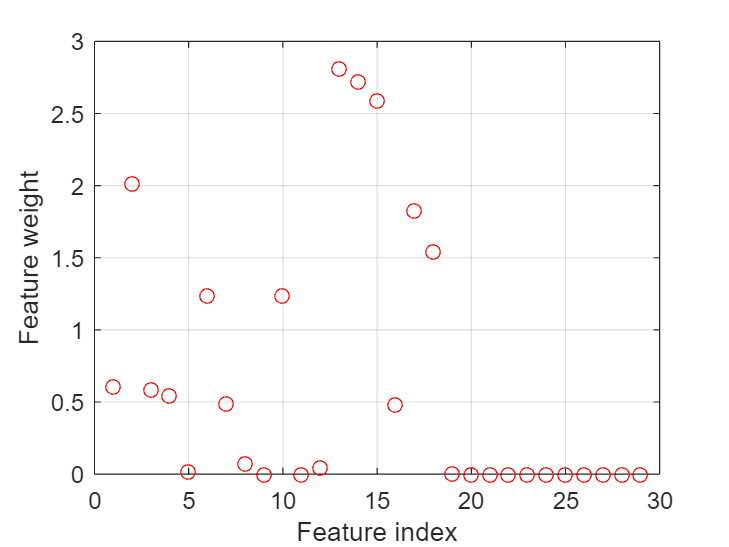

figure()
plot(ncaBest.FeatureWeights,'ro')
grid on
xlabel('Feature index')
ylabel('Feature weight')

#### testing the embedded NCA

fitted = predict(ncaBest, Xtest)

fitted =     0.0675
    0.0526
    0.2258
    0.2816
    0.1533
    0.3039
    0.2757
    0.2954
    0.3954
    0.5032


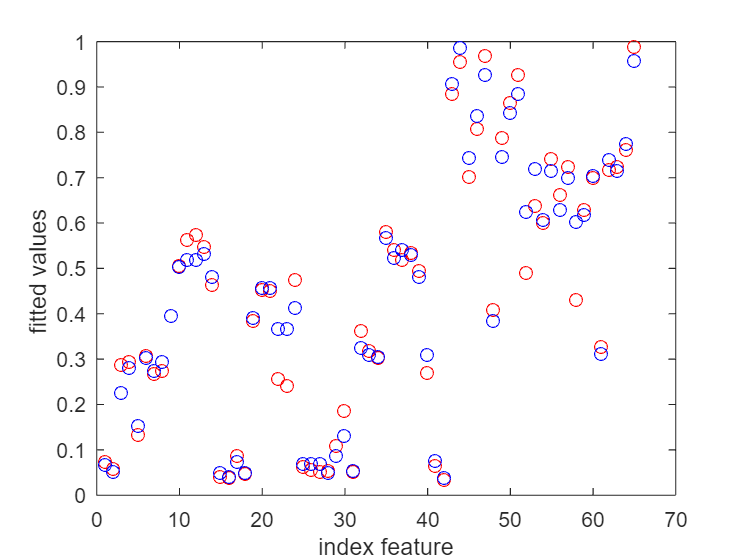

plot(Ytest, 'ro')
hold on 
plot(fitted, 'bo')
xlabel('index feature')
ylabel('fitted values ')

lossvalue = loss(ncaBest, Xtest, Ytest,'LossFunction','mad')

lossvalue = 0.0275

weights = ncaBest.FeatureWeights

weights =     0.2410
    1.9852
    0.0667
    1.4990
    0.0026
    1.6125
    0.6476
    1.1897
    0.0008
    1.2965


[weightsScores, weightsIndices] = sort(weights, 'descend')

weightsScores =     3.9007
    1.9852
    1.9448
    1.6125
    1.5996
    1.5468
    1.4990
    1.2965
    1.1897
    0.9707


weightsIndices =     13
     2
    18
     6
    15
    17
     4
    10
     8
    14


% only taking 10 best features
fsNCA = lablesE(1,weightsIndices(1:10))

fsNCA = 1×10 table
         lables13                 lables2                     lables28                   lables6             lables18          lables23          lables4             lables10                     lables8                lables14  
    __________________    ________________________    _________________________    ____________________    _____________    ______________    ______________    ___________________    _____________________________    ___________

    {'WeightImpurity'}    {'Matrix_crystallinity'}    {'MajorityPolymer_HDPE1'}    {'Matrix_viscosity'}    {'impurityE'}    {'impurityXc'}    {'Matrix_SCB'}    {'Contaminant_SCB'}    {


%  no threshold needed, take just only 10 best 
% idxNCA = zeros(length(weights),1)
% counter= 1;
% for i= 1: length(weights)
%     if weights(i) > 1
%         idxNCA(counter, 1) = 
%         counter = counter + 1; 
%     end
% end
% idxNCA = idxNCA(idxNCA~= 0)

#### F-test

[idx,scores] = fsrftest(Xe,Ye);
% the values in scores are the negative logs of the p-values
find(isinf(scores)) 


ans =

  1×0 empty double row vector



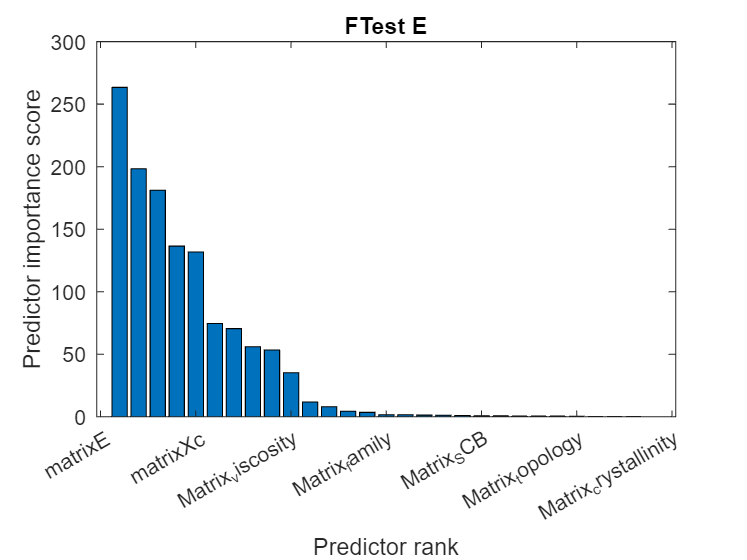

% no neg pvalues, meaning null hypothesis??
figure;
bar(scores(idx))
xticks('auto')
xticklabels(table2cell(lablesE(1,idx)))
xlabel('Predictor rank')
ylabel('Predictor importance score')
title('FTest E')


fsFTEST = lablesE(1,idx(1:10));
relevant_features_ftest = E(:,idx);
% scrs = sorted(scores, 'descend')
% figure; 
% plot(scores(idx),relevant_features_names)
% xlabel('Predictor rank')
% ylabel('Predictor importance score')


scatter3(relevant_features_ftest(:,1),relevant_features_ftest(:,2) ,Ye)
corr(relevant_features_ftest(:,1), Ye)

ans = 0.9204

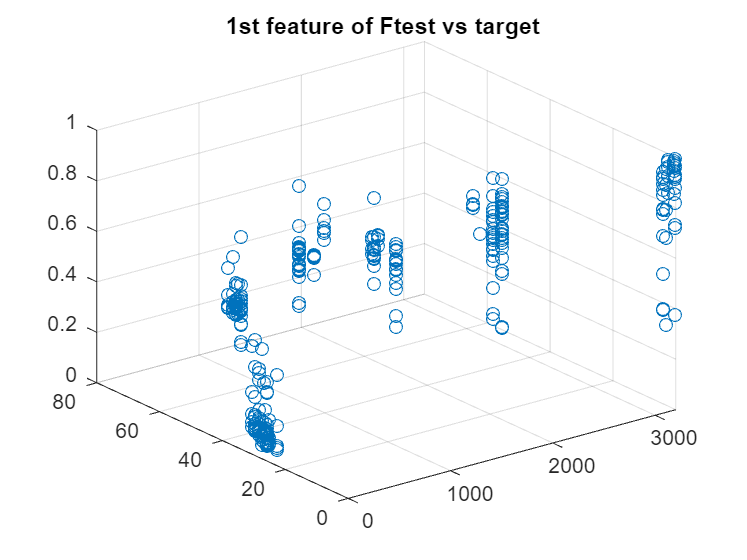

title('1st feature of Ftest vs target ')

#### Spearman's correlation

%spearman correlation in whole datset
sc=spearman_corr_n_best(Xe, Ye, 10)

sc_n =     14
     4
     1
     3
     6
    19
    20
    16
     5
    21


sc =     14
     4
     1
     3
     6
    19
    20
    16
     5
    21


fsSC = lablesE(1,sc)

fsSC = 1×10 table
     lables14         lables4             lables1               lables3                lables6                   lables29                      lables30               lables22         lables5               lables31        
    ___________    ______________    _________________    ___________________    ____________________    _________________________    __________________________    ____________    ______________    _______________________

    {'matrixE'}    {'Matrix_SCB'}    {'Matrix_family'}    {'Matrix_topology'}    {'Matrix_viscosity'}    {'MajorityPolymer_LDPE1'}    {'MajorityPolymer_LLDPE1'}    {'matrixXc'}    {'Matrix_LCB'}   

#### MRMR

[idxmrmr, scoresmrmr] = fsrmrmr(Xe,Ye);
figure()
bar(scoresmrmr(idxmrmr))

fsMRMR = lablesE(1,idxmrmr(1:10))

fsMRMR = 1×10 table
     lables14           lables13                lables37                    lables29                lables4               lables35                 lables1                 lables2                   lables3                  lables28         
    ___________    __________________    _______________________    _________________________    ______________    _______________________    _________________    ________________________    ___________________    _________________________

    {'matrixE'}    {'WeightImpurity'}    {'MajorityPolymer_PS2'}    {'MajorityPolymer_LDPE1'}    {'Matrix_SCB'}    {'MajorityPolymer_PP3'}    {'Matrix_family'}

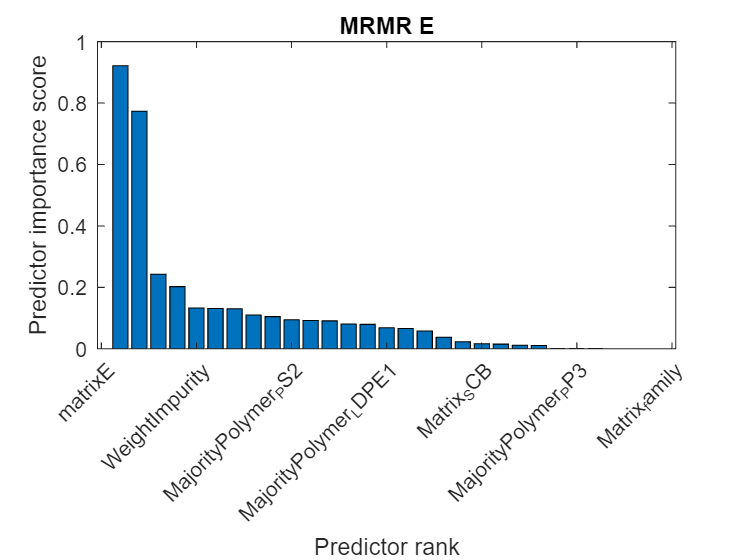

xlabel("Predictor rank")
ylabel("Predictor importance score")
title('MRMR E')
% predictorNames = cartable.Properties.VariableNames(1:end-1);
% xticklabels(strrep(rankF_mrmr,"_","\_"))
xticklabels(table2cell(fsMRMR))
xtickangle(45) 

FOR NCA AND MRMR MAJORITY LDPE IS AN IMPORTANT FETAURE

#### ensembeling an array with all results given results of NCA MRMR FTEST SPEARCORR RFPER

for simplicicty keep always this order 

%adding permutation imprtance
rf_idx = table2array(PER(2,:))

rf_idx =     13    12    14    15    16     9     1    25     6    35


fsPER = lablesE(1,rf_idx)

fsPER = 1×10 table
         lables13                 lables12              lables14        lables18         lables22              lables9                  lables1                lables35                  lables6                  lables45        
    __________________    _________________________    ___________    _____________    ____________    ________________________    _________________    _______________________    ____________________    _______________________

    {'WeightImpurity'}    {'Contaminant_viscosity'}    {'matrixE'}    {'impurityE'}    {'matrixXc'}    {'Contaminant_topology'}    {'Matrix_family'}    {'MajorityPolymer_PP3'}    {'Matri

features= [table2array(fsNCA), table2array(fsMRMR),table2array(fsFTEST), table2array(fsSC) , table2array(fsPER)]

features = 1×50 cell array
    {'WeightImpurity'}    {'Matrix_crystallinity'}    {'MajorityPolymer_HDPE1'}    {'Matrix_viscosity'}    {'impurityE'}    {'impurityXc'}    {'Matrix_SCB'}    {'Contaminant_SCB'}    {'Contaminant_crystallinity'}    {'matrixE'}    {'matrixE'}    {'WeightImpurity'}    {'MajorityPolymer_PS2'}    {'MajorityPolymer_LDPE1'}    {'Matrix_SCB'}    {'MajorityPolymer_PP3'}    {'Matrix_family'}    {'Matrix_crystallinity'}    {'Matrix_topology'}    {'MajorityPolymer_HDPE1'}    {'matrixE'}    {'matrixXc'}    {'Matrix_viscosity'}    {'Matrix_family'}    {'Matrix_SCB'}    {'Matrix_topology'}    {'Matrix_crystallinity'}    {'MajorityPolymer_LDPE1'}    {'Matrix_LCB'}    {'MajorityPolymer_LLDPE1'}    {'matrixE'}    {'Matrix_SCB'}    {'Matrix_family'}    {'Matrix_topology'}    {'Matrix_viscosity'}    {'MajorityPolymer_LDPE1'}    {'MajorityPolymer_LLDPE1'}    {'matrixXc'}    {'Matrix_LCB'}    {'MajorityPolymer_PA1'}    {'WeightImpurity'}    {'Contaminant_viscosity'}    {'matrixE


%USING BORDA COUNT 
% Find unique strings
%uniqueF= unique(features);
% 
% % Initialize an array to store the weighted occurrences
% weightedOccurrences = zeros(size(uniqueF));
% 
% % Calculate weighted occurrences based on position
% for i = 1:numel(features)
%     % + (11- mod(i, 10))
%     stringIndex = find(strcmp(uniqueF, features{i})); % Find the index of the string
%     weightedOccurrences(stringIndex) = weightedOccurrences(stringIndex) + + (11- mod(i, 10)); % Assign weight based on position ORIGINAL POSITION, GIVEN IT GOES BY 10S MOD - 11
% end
% figure()
% % Plot the weighted frequency of occurrence
% bar(1:numel(uniqueF), weightedOccurrences)
% xticks(1:numel(uniqueF))
% xticklabels(uniqueF)
% title('Sum of ranking per Feature WHOLE')
% xlabel('features ')
% ylabel('Total sum rank')

### TRYING WITH SMALLER DATASETS

they have 1HE and the other features! so reduce!! 

#### POLY AND NON POLYEFINE only elasticity

Do exactly the same metholody before but applying all techniques to both partitions, the general feature array for both partitions will have the same order as before. 

P = readtable('data_reduced_p.csv');
 % cannot becasuse 1hor encondings give inf 
% P = normalize(P)
NP = readtable('data_reduced_np.csv');

% because of ârtition the first col(matrix family) will not be relevant 
P =  table2array(P(:,[1 2 3 4 5 6 7 8 9 10 11 12 13 14 18 22 23 24 28 29 30 31 40 41 42 43 44 45 46 47  ]))

P = 1.0e+03 *

         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020    0.0010         0         0    0.0050    0.0005    0.1924    0.9529    0.0327    0.0651    0.4624         0    0.0010         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020    0.0010         0         0    0.0050    0.0002    0.1924    0.9529    0.0327    0.0651    0.2918         0    0.0010         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020    0.0010         0         0    0.0050    0.0001    0.1924    0.9529    0.0327    0.0651    0.2380         0    0.0010         0         0         0         0         0         0         0         0         0         0
         0    0.0010         0    0.0010    0.0020    0.0020         0    0.0020  

NP = table2array(NP(:,[1 2 3 4 5 6 7 8 9 10 11 12 13 14 18 22 23 24 28 29 30 31 40 41 42 43 44 45 46 47  ]))

NP = 1.0e+03 *

    0.0010         0    0.0010         0         0    0.0030         0    0.0020    0.0010         0         0    0.0050    0.0005    3.0839    0.9845         0    0.0660    1.7811         0         0         0         0         0         0         0         0         0         0         0         0
    0.0010         0    0.0010         0         0    0.0030         0    0.0020    0.0010         0         0    0.0050    0.0002    3.0839    0.9845         0    0.0660    2.6098         0         0         0         0         0         0         0         0         0         0         0         0
    0.0010         0    0.0010         0         0    0.0030         0    0.0020    0.0010         0         0    0.0050    0.0001    3.0839    0.9845         0    0.0660    2.8575         0         0         0         0         0         0         0         0         0         0         0         0
    0.0010         0    0.0010         0         0    0.0030         0    0.0020 


% separate cols and norm
x_p= [P(:,1:17), P(:,19:end)];
y_p = P(:,18)/max(E(:,18));
x_np= [NP(:,1:17), NP(:,19:end)];
y_np = NP(:,18)/max(E(:,18));
cc_p = x_p(:,14:17) ./ max(x_p(:,14:17));   x_p(:,14:17)= cc_p

x_p =          0    1.0000         0    1.0000    2.0000    2.0000         0    2.0000    1.0000         0         0    5.0000    0.5000    0.1087    0.2976    0.4860    1.0000         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0    1.0000    2.0000    2.0000         0    2.0000    1.0000         0         0    5.0000    0.2000    0.1087    0.2976    0.4860    1.0000         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0    1.0000    2.0000    2.0000         0    2.0000    1.0000         0         0    5.0000    0.1000    0.1087    0.2976    0.4860    1.0000         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0    1.0000    2.0000    2.0000         0    2.0000    1.0000         0         0    5.0000 

cc_np = x_np(:,14:17) ./ max(x_np(:,14:17));    x_np(:,14:17)= cc_np

x_np =     1.0000         0    1.0000         0         0    3.0000         0    2.0000    1.0000         0         0    5.0000    0.5000    0.9631    0.3087         0    0.9812         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0    1.0000         0         0    3.0000         0    2.0000    1.0000         0         0    5.0000    0.2000    0.9631    0.3087         0    0.9812         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0    1.0000         0         0    3.0000         0    2.0000    1.0000         0         0    5.0000    0.1000    0.9631    0.3087         0    0.9812         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0    1.0000         0         0    3.0000         0    2.0000    1.0000         0         0    5.0000

% fast splitting 10% of data ->32.8 instances 
[rP, cP ]=size(x_p)

rP = 219

cP = 29

PD = 0.90 ;
idx = randperm(rP);
XPtrain = x_p(idx(1:round(rP*PD)),:);
XPtest = x_p(idx(round(rP*PD)+1:end),:);
YPtrain = y_p(idx(1:round(rP*PD)),:);
YPtest = y_p(idx(round(rP*PD)+1:end),:);

[rNP, cNP ]=size(x_np)

rNP = 109

cNP = 29

idx = randperm(rNP);
XNPtrain = x_np(idx(1:round(rNP*PD)),:);
XNPtest = x_np(idx(round(rNP*PD)+1:end),:);
YNPtrain = y_np(idx(1:round(rNP*PD)),:);
YNPtest = y_np(idx(round(rNP*PD)+1:end),:);
% fitmethod : exact

nca_p = fsrnca(x_p, y_p, 'Verbose',2, 'Standardize',true, 'Solver','sgd', 'Lambda',bestlambda)


 o Tuning initial learning rate: NumTuningIterations = 20, TuningSubsetSize = 100

|===============================================|
|    TUNING    | TUNING SUBSET |    LEARNING    |
|     ITER     |   FUN VALUE   |      RATE      |
|===============================================|
|            1 |  6.543169e-02 |   2.000000e-01 |
|            2 |  6.416582e-02 |   4.000000e-01 |
|            3 |  6.206064e-02 |   8.000000e-01 |
|            4 |  5.913050e-02 |   1.600000e+00 |
|            5 |  5.421476e-02 |   3.200000e+00 |
|            6 |  4.615064e-02 |   6.400000e+00 |
|            7 |  3.999946e-02 |   1.280000e+01 |
|            8 |  3.670233e-02 |   2.560000e+01 |
|            9 |  3.587743e-02 |   5.120000e+01 |
|           10 |  3.587743e-02 |   5.120000e+01 |
|           11 |  3.587743e-02 |   5.120000e+01 |
|           12 |  3.587743e-02 |   5.120000e+01 |
|           13 |  3.587743e-02 |   5.120000e+01 |
|           14 |  3.447076e-02 |   1.024000e+02 |
|           15 |

nca_p =   FeatureSelectionNCARegression
          NumObservations: 219
          ModelParameters: [1×1 struct]
                   Lambda: 6.4185e-04
                FitMethod: 'exact'
                   Solver: 'sgd'
        GradientTolerance: 1.0000e-06
           IterationLimit: 10000
                PassLimit: 5
      InitialLearningRate: []
                  Verbose: 2
    InitialFeatureWeights: [29×1 double]
           FeatureWeights: [29×1 double]
                  FitInfo: [1×1 struct]
                       Mu: [29×1 double]
                    Sigma: [29×1 double]
                        X: [219×29 double]
                        Y: [219×1 double]
                        W: [219×1 double]


  Properties, Methods


nca_np = fsrnca(x_np, y_np, 'Verbose',2, 'Standardize',true, 'Solver','sgd', 'Lambda',bestlambda)


 o Tuning initial learning rate: NumTuningIterations = 20, TuningSubsetSize = 100

|===============================================|
|    TUNING    | TUNING SUBSET |    LEARNING    |
|     ITER     |   FUN VALUE   |      RATE      |
|===============================================|
|            1 |  1.017862e-01 |   2.000000e-01 |
|            2 |  9.624090e-02 |   4.000000e-01 |
|            3 |  8.550287e-02 |   8.000000e-01 |
|            4 |  7.420132e-02 |   1.600000e+00 |
|            5 |  6.801027e-02 |   3.200000e+00 |
|            6 |  6.224047e-02 |   6.400000e+00 |
|            7 |  5.856143e-02 |   1.280000e+01 |
|            8 |  5.787666e-02 |   2.560000e+01 |
|            9 |  5.266128e-02 |   5.120000e+01 |
|           10 |  5.266128e-02 |   5.120000e+01 |
|           11 |  5.266128e-02 |   5.120000e+01 |
|           12 |  5.131749e-02 |   1.024000e+02 |
|           13 |  5.131749e-02 |   1.024000e+02 |
|           14 |  4.975576e-02 |   5.120000e+01 |
|           15 |

nca_np =   FeatureSelectionNCARegression
          NumObservations: 109
          ModelParameters: [1×1 struct]
                   Lambda: 6.4185e-04
                FitMethod: 'exact'
                   Solver: 'sgd'
        GradientTolerance: 1.0000e-06
           IterationLimit: 10000
                PassLimit: 5
      InitialLearningRate: []
                  Verbose: 2
    InitialFeatureWeights: [29×1 double]
           FeatureWeights: [29×1 double]
                  FitInfo: [1×1 struct]
                       Mu: [29×1 double]
                    Sigma: [29×1 double]
                        X: [109×29 double]
                        Y: [109×1 double]
                        W: [109×1 double]


  Properties, Methods



fittedP= predict(nca_p, XPtrain);
fittedNP= predict(nca_np, XNPtrain);
loss_p = loss(nca_p,XPtest,YPtest,'LossFunction','mad') 

loss_p = 0.0056

loss_np = loss(nca_np,XNPtest,YNPtest,'LossFunction','mad') 

loss_np = 0.0143

 NP = default 3.5283e-04 ; P =4.931e-04

standarizing : NP = 0.0199, P = 0.0219

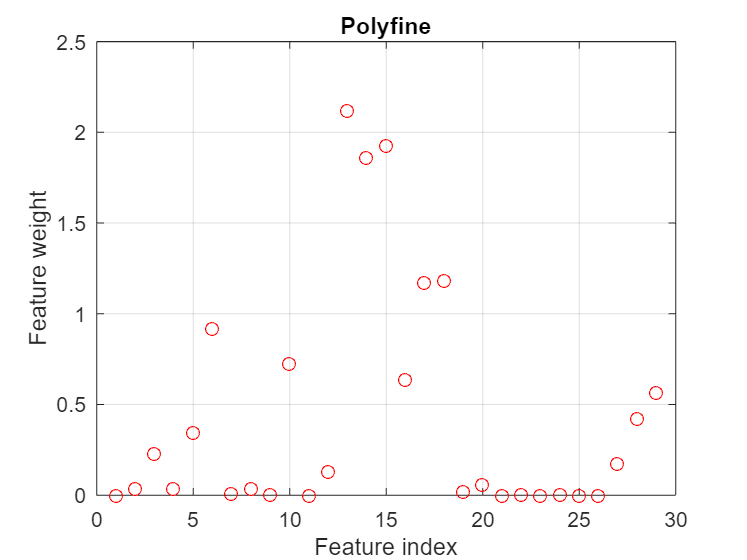

figure()
plot(nca_p.FeatureWeights,'ro')
grid on
%  hold on 
% plot(nca_np.FeatureWeights,'bo')
% hold off
xlabel('Feature index')
ylabel('Feature weight')
title('Polyfine')

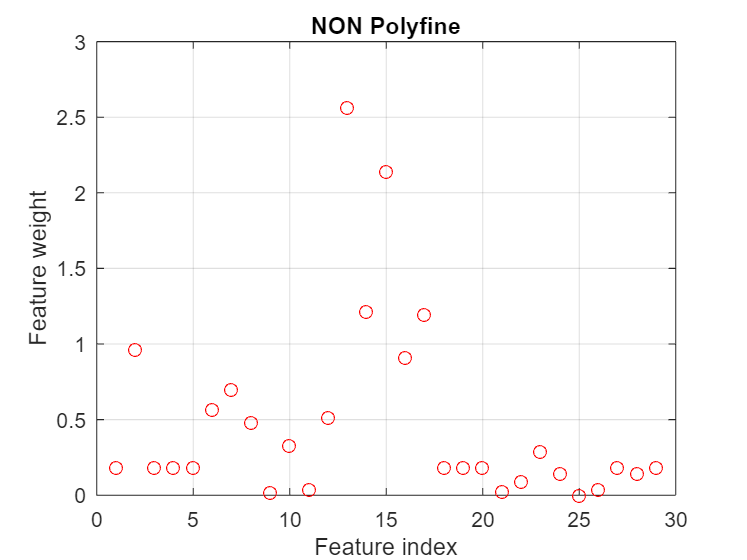


figure()
plot(nca_np.FeatureWeights,'ro')
grid on
xlabel('Feature index')
ylabel('Feature weight')
title('NON Polyfine')

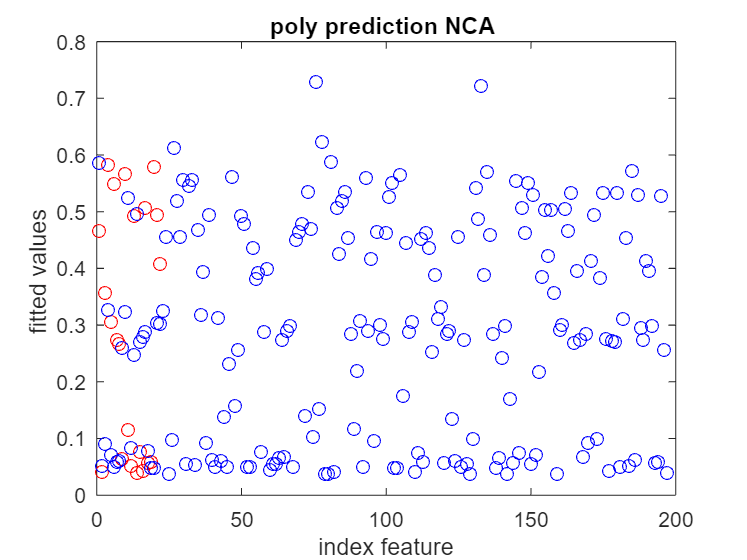


figure()
plot(YPtest, 'ro')
hold on 
plot(fittedP, 'bo')
title('poly prediction NCA ')
xlabel('index feature')
ylabel('fitted values ')

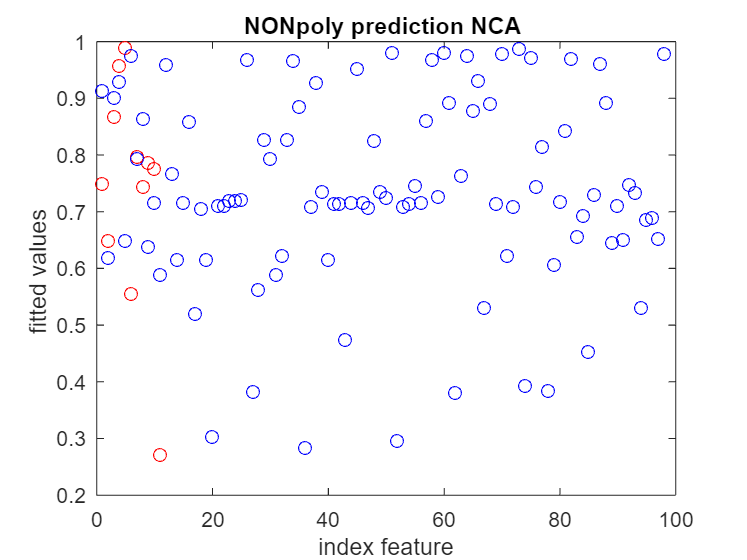


figure()
plot(YNPtest, 'ro')
hold on 
plot(fittedNP, 'bo')
title('NONpoly prediction NCA ')
xlabel('index feature')
ylabel('fitted values ')

weightsP = nca_p.FeatureWeights

weightsP =     0.0010
    0.0395
    0.2299
    0.0395
    0.3483
    0.9214
    0.0118
    0.0366
    0.0021
    0.7247


weightsNP = nca_np.FeatureWeights

weightsNP =     0.1851
    0.9643
    0.1851
    0.1851
    0.1851
    0.5676
    0.7016
    0.4828
    0.0175
    0.3256



[weightsScores, wP] = sort(weightsP, 'descend')

weightsScores =     2.1202
    1.9251
    1.8616
    1.1851
    1.1711
    0.9214
    0.7247
    0.6354
    0.5681
    0.4213


wP =     13
    15
    14
    18
    17
     6
    10
    16
    29
    28


[~, wNP] = sort(weightsNP, 'descend')

wNP =     13
    15
    14
    17
     2
    16
     7
     6
    12
     8


% only taking 10 best features
fsNCA_p = lablesE(1,wP(1:10))

fsNCA_p = 1×10 table
         lables13           lables18        lables14              lables28                lables23             lables6                lables10            lables22              lables39                     lables38         
    __________________    _____________    ___________    _________________________    ______________    ____________________    ___________________    ____________    _________________________    _________________________

    {'WeightImpurity'}    {'impurityE'}    {'matrixE'}    {'MajorityPolymer_HDPE1'}    {'impurityXc'}    {'Matrix_viscosity'}    {'Contaminant_SCB'}    {'matrixXc'}    {'MinorityPolymer_LDPE1'

fsNCA_np = lablesE(1,wNP(1:10))

fsNCA_np = 1×10 table
         lables13           lables18        lables14         lables23               lables2               lables22             lables7                  lables6                   lables12                        lables8           
    __________________    _____________    ___________    ______________    ________________________    ____________    ______________________    ____________________    _________________________    _____________________________

    {'WeightImpurity'}    {'impurityE'}    {'matrixE'}    {'impurityXc'}    {'Matrix_crystallinity'}    {'matrixXc'}    {'Contaminant_family'}    {'Matrix_viscosity'}    {'Contami

% first col; matrix fam 
[idxP,scoresP] = fsrftest(x_p(:,2:end),y_p);
[idxNP,scoresNP] = fsrftest(x_np(:,2:end) , y_np);
find(isinf(scores)) 


ans =

  1×0 empty double row vector



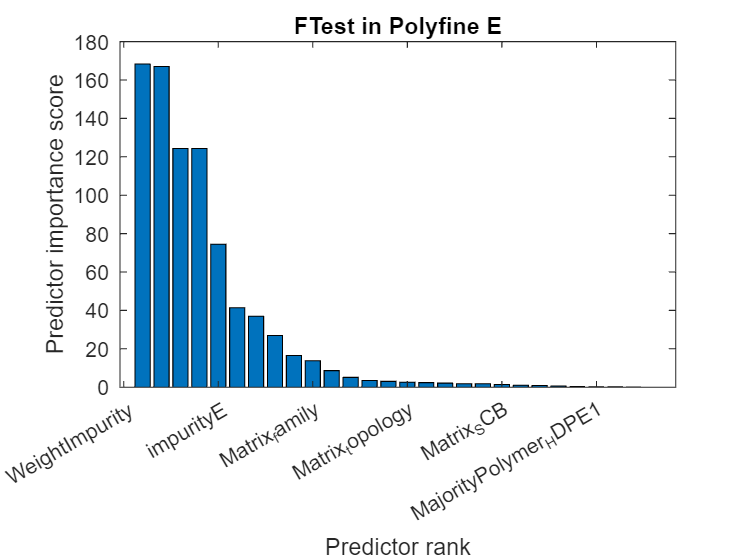

% no neg pvalues, no inf values, test is approppiate 
figure()
bar(scoresP(idxP))
xticks('auto')
xticklabels(table2cell(lablesE(1,idxP)))
xlabel('Predictor rank')
ylabel('Predictor importance score')
title('FTest in Polyfine E')

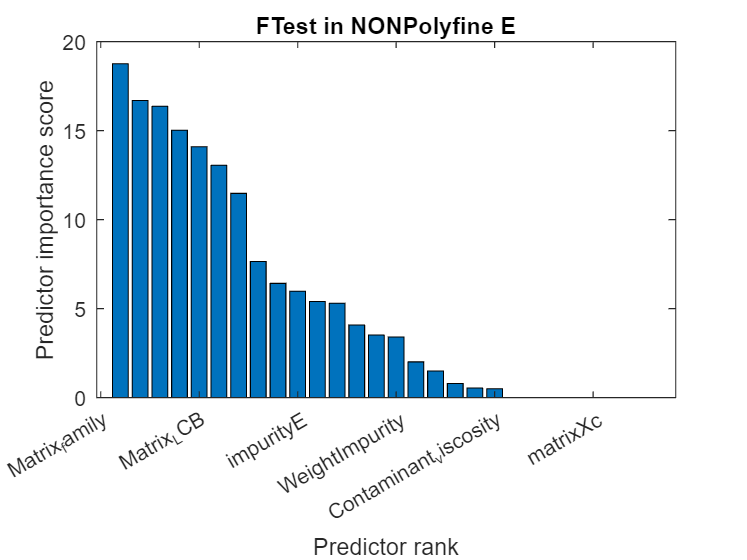


figure()
bar(scoresNP(idxNP))
xticks('auto')
xticklabels(table2cell(lablesE(1,idxNP)))
xlabel('Predictor rank')
ylabel('Predictor importance score')
title('FTest in NONPolyfine E')

fsFTEST_p = lablesE(1,idxP(1:10))

fsFTEST_p = 1×10 table
         lables13           lables18            lables1               lables3             lables4                lables28                lables5                lables29                     lables2              lables14  
    __________________    _____________    _________________    ___________________    ______________    _________________________    ______________    _________________________    ________________________    ___________

    {'WeightImpurity'}    {'impurityE'}    {'Matrix_family'}    {'Matrix_topology'}    {'Matrix_SCB'}    {'MajorityPolymer_HDPE1'}    {'Matrix_LCB'}    {'MajorityPolymer_LDPE1'}    {'Matrix_crys

fsFTEST_np = lablesE(1,idxNP(1:10))

fsFTEST_np = 1×10 table
         lables1            lables5          lables18            lables13                 lables12               lables22       lables14              lables9                   lables6                    lables30         
    _________________    ______________    _____________    __________________    _________________________    ____________    ___________    ________________________    ____________________    __________________________

    {'Matrix_family'}    {'Matrix_LCB'}    {'impurityE'}    {'WeightImpurity'}    {'Contaminant_viscosity'}    {'matrixXc'}    {'matrixE'}    {'Contaminant_topology'}    {'Matrix_viscosity'}   

MRMR is sort of a clustering alg that ranks the features of how well they can 'ressemble' the prediction, 

givne what we saw PCA a clustering technique would not be too off what the prediction as there are three main families adn each run in different ranges by general rule. 


[imrP, scoresP] = fsrmrmr(x_p,y_p);
[imrNP, scoresNP] = fsrmrmr(x_np,y_np);

fsMRMR_p = lablesE(1,imrP(1:10))

fsMRMR_p = 1×10 table
      lables22             lables33                 lables13                lables36               lables4                lables2                     lables28                lables5                 lables30                    lables35        
    ____________    _______________________    __________________    _______________________    ______________    ________________________    _________________________    ______________    __________________________    _______________________

    {'matrixXc'}    {'MajorityPolymer_PP1'}    {'WeightImpurity'}    {'MajorityPolymer_PS1'}    {'Matrix_SCB'}    {'Matrix_crystallinity'}    {'Majorit

fsMRMR_np = lablesE(1,imrNP(1:10))

fsMRMR_np = 1×10 table
          lables6             lables18               lables2                    lables36                   lables7              lables22              lables38                    lables34                    lables32             lables14  
    ____________________    _____________    ________________________    _______________________    ______________________    ____________    _________________________    _______________________    ________________________    ___________

    {'Matrix_viscosity'}    {'impurityE'}    {'Matrix_crystallinity'}    {'MajorityPolymer_PS1'}    {'Contaminant_family'}    {'matrixXc'}    {'MinorityPolymer_

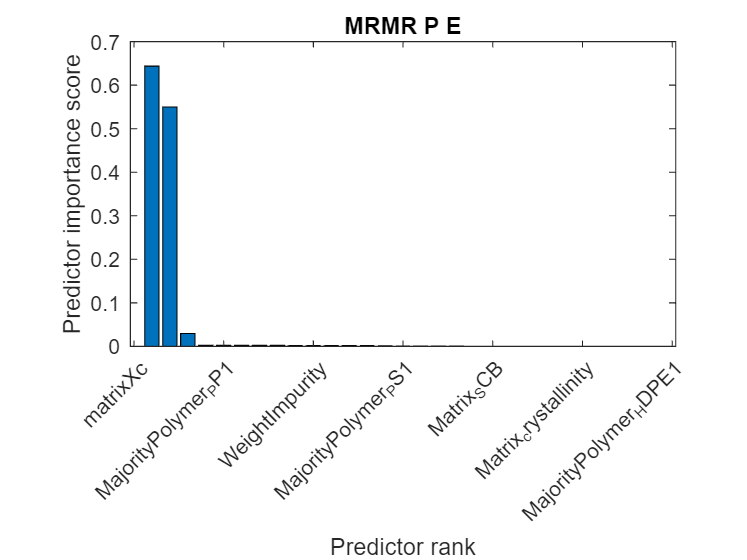


figure()
bar(scoresP(imrP))
xlabel("Predictor rank")
ylabel("Predictor importance score")
title('MRMR P E')
xticklabels(table2cell(fsMRMR_p))
xtickangle(45)

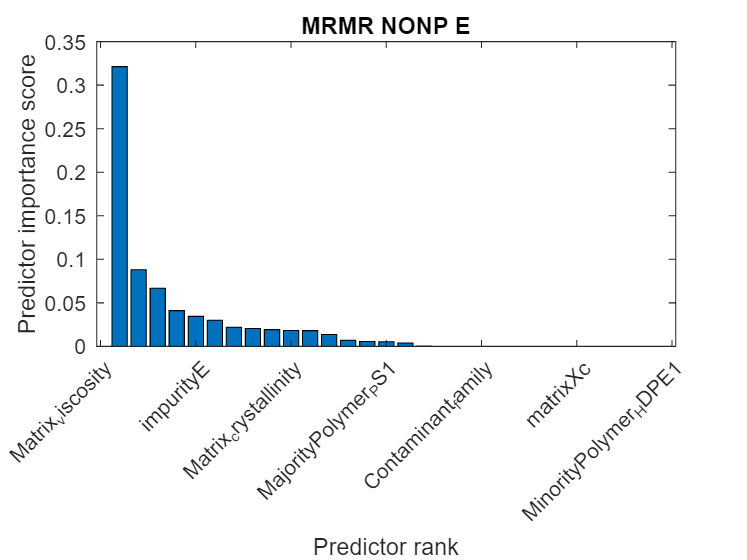


figure()
bar(scoresNP(imrNP))
xlabel("Predictor rank")
ylabel("Predictor importance score")
title('MRMR NONP E')
xticklabels(table2cell(fsMRMR_np))
xtickangle(45)

sc_p=spearman_corr_n_best(x_p, y_p, 10)

sc_n =      1
    21
    14
     2
     4
    16
    20
    19
     6
     3


sc_p =      1
    21
    14
     2
     4
    16
    20
    19
     6
     3


fsSC_p = lablesE(1,sc_p)

fsSC_p = 1×10 table
         lables1                lables31             lables14              lables2                lables4          lables22               lables30                     lables29                   lables6                 lables3      
    _________________    _______________________    ___________    ________________________    ______________    ____________    __________________________    _________________________    ____________________    ___________________

    {'Matrix_family'}    {'MajorityPolymer_PA1'}    {'matrixE'}    {'Matrix_crystallinity'}    {'Matrix_SCB'}    {'matrixXc'}    {'MajorityPolymer_LLDPE1'}    {'MajorityPolyme

sc_np=spearman_corr_n_best(x_np, y_np, 10)

sc_n =      1
     3
     4
     5
    18
    19
    20
    27
    29
     2


sc_np =      1
     3
     4
     5
    18
    19
    20
    27
    29
     2


fsSC_np = lablesE(1,sc_np)

fsSC_np = 1×10 table
         lables1               lables3             lables4           lables5                lables28                     lables29                      lables30                    lables37                    lables39                     lables2         
    _________________    ___________________    ______________    ______________    _________________________    _________________________    __________________________    _______________________    _________________________    ________________________

    {'Matrix_family'}    {'Matrix_topology'}    {'Matrix_SCB'}    {'Matrix_LCB'}    {'MajorityPolymer_HDPE1'}    {'MajorityPolymer_L

rf_p = table2array(PER(3,:))

rf_p =     13    12    15     3     1    16    14     6    35     7


fsPER_p = lablesE(1,rf_p)

fsPER_p = 1×10 table
         lables13                 lables12               lables18             lables3               lables1           lables22       lables14            lables6                  lables45                   lables7        
    __________________    _________________________    _____________    ___________________    _________________    ____________    ___________    ____________________    _______________________    ______________________

    {'WeightImpurity'}    {'Contaminant_viscosity'}    {'impurityE'}    {'Matrix_topology'}    {'Matrix_family'}    {'matrixXc'}    {'matrixE'}    {'Matrix_viscosity'}    {'MinorityPolymer_PP3'}  

rf_np = table2array(PER(4,:))

rf_np =     12    14     9    16    25    11     7     6     8    35


fsPER_np = lablesE(1,rf_np)

fsPER_np = 1×10 table
            lables12              lables14              lables9               lables22             lables35                 lables11                 lables7                  lables6                      lables8                      lables45        
    _________________________    ___________    ________________________    ____________    _______________________    ___________________    ______________________    ____________________    _____________________________    _______________________

    {'Contaminant_viscosity'}    {'matrixE'}    {'Contaminant_topology'}    {'matrixXc'}    {'MajorityPolymer_PP3'}    {'Contaminant_LCB'} 

features_p = [table2array(fsNCA_p), table2array(fsMRMR_p),table2array(fsFTEST_p), table2array(fsSC_p), table2array(fsPER_p)]

features_p = 1×50 cell array
    {'WeightImpurity'}    {'impurityE'}    {'matrixE'}    {'MajorityPolymer_HDPE1'}    {'impurityXc'}    {'Matrix_viscosity'}    {'Contaminant_SCB'}    {'matrixXc'}    {'MinorityPolymer_LDPE1'}    {'MinorityPolymer_HDPE1'}    {'matrixXc'}    {'MajorityPolymer_PP1'}    {'WeightImpurity'}    {'MajorityPolymer_PS1'}    {'Matrix_SCB'}    {'Matrix_crystallinity'}    {'MajorityPolymer_HDPE1'}    {'Matrix_LCB'}    {'MajorityPolymer_LLDPE1'}    {'MajorityPolymer_PP3'}    {'WeightImpurity'}    {'impurityE'}    {'Matrix_family'}    {'Matrix_topology'}    {'Matrix_SCB'}    {'MajorityPolymer_HDPE1'}    {'Matrix_LCB'}    {'MajorityPolymer_LDPE1'}    {'Matrix_crystallinity'}    {'matrixE'}    {'Matrix_family'}    {'MajorityPolymer_PA1'}    {'matrixE'}    {'Matrix_crystallinity'}    {'Matrix_SCB'}    {'matrixXc'}    {'MajorityPolymer_LLDPE1'}    {'MajorityPolymer_LDPE1'}    {'Matrix_viscosity'}    {'Matrix_topology'}    {'WeightImpurity'}    {'Contaminant_viscosity'}    {

features_np = [table2array(fsNCA_np), table2array(fsMRMR_np),table2array(fsFTEST_np),table2array(fsSC_np),table2array(fsPER_np) ]

features_np = 1×50 cell array
    {'WeightImpurity'}    {'impurityE'}    {'matrixE'}    {'impurityXc'}    {'Matrix_crystallinity'}    {'matrixXc'}    {'Contaminant_family'}    {'Matrix_viscosity'}    {'Contaminant_viscosity'}    {'Contaminant_crystallinity'}    {'Matrix_viscosity'}    {'impurityE'}    {'Matrix_crystallinity'}    {'MajorityPolymer_PS1'}    {'Contaminant_family'}    {'matrixXc'}    {'MinorityPolymer_HDPE1'}    {'MajorityPolymer_PP2'}    {'MajorityPolymer_PET1'}    {'matrixE'}    {'Matrix_family'}    {'Matrix_LCB'}    {'impurityE'}    {'WeightImpurity'}    {'Contaminant_viscosity'}    {'matrixXc'}    {'matrixE'}    {'Contaminant_topology'}    {'Matrix_viscosity'}    {'MajorityPolymer_LLDPE1'}    {'Matrix_family'}    {'Matrix_topology'}    {'Matrix_SCB'}    {'Matrix_LCB'}    {'MajorityPolymer_HDPE1'}    {'MajorityPolymer_LDPE1'}    {'MajorityPolymer_LLDPE1'}    {'MajorityPolymer_PS2'}    {'MinorityPolymer_LDPE1'}    {'Matrix_crystallinity'}    {'Contaminant_viscosity'}    

## **crystallinity**

AC = readtable('data_reduced_amorp_crys.csv');
LC = readtable('data_reduced_low_crys.csv');
HC = readtable('data_reduced_high_crys.csv');

% because of ârtition the first col(matrix family) will not be relevant 
AC =  table2array(AC(:,[1 2 3 4 5 6 7 8 9 10 11 12 13 14 18 22 23 24 28 29 30 31 40 41 42 43 44 45 46 47  ]));
LC  =  table2array(LC(:,[1 2 3 4 5 6 7 8 9 10 11 12 13 14 18 22 23 24 28 29 30 31 40 41 42 43 44 45 46 47  ]));
HC  =  table2array(HC(:,[1 2 3 4 5 6 7 8 9 10 11 12 13 14 18 22 23 24 28 29 30 31 40 41 42 43 44 45 46 47  ]));
x_ac= [AC(:,1:17), AC(:,19:end)]

x_ac = 1.0e+03 *

    0.0010         0    0.0010         0         0    0.0030         0    0.0020    0.0010         0         0    0.0050    0.0005    3.0839    0.9845         0    0.0660         0         0         0         0         0         0         0         0         0         0         0         0
    0.0010         0    0.0010         0         0    0.0030         0    0.0020    0.0010         0         0    0.0050    0.0002    3.0839    0.9845         0    0.0660         0         0         0         0         0         0         0         0         0         0         0         0
    0.0010         0    0.0010         0         0    0.0030         0    0.0020    0.0010         0         0    0.0050    0.0001    3.0839    0.9845         0    0.0660         0         0         0         0         0         0         0         0         0         0         0         0
    0.0010         0    0.0010         0         0    0.0030         0    0.0020    0.0010         0         

y_ac = AC(:,18) ./ max(AC(:,18))

y_ac =     0.5523
    0.8093
    0.8861
    0.9356
    0.9563
    0.3780
    0.7211
    0.8216
    0.8787
    0.9930


x_lc= [LC(:,1:17), LC(:,19:end)];
y_lc = LC(:,18)./ max(LC(:,18))

y_lc =     0.1653
    0.1043
    0.0851
    0.0716
    0.0755
    0.0710
    0.0688
    0.0496
    0.0567
    0.0601


x_hc= [HC(:,1:17), HC(:,19:end)];
y_hc = HC(:,18)./ max(HC(:,18))

y_hc =     0.1959
    0.2961
    0.3643
    0.3690
    0.3681
    0.3788
    0.4036
    0.1834
    0.2904
    0.3370



if  max(x_ac(:, 16)) == 0
    max_value = 1e-6; % Set a small non-zero value if the maximum value is zeroelse 
    x_ac(:,16) = x_ac(:,16)./ max_value
    x_ac(:,14:15) = x_ac(:,14:15) ./max(x_ac(:,14:15))
    x_ac(:,17) = x_ac(:,17) ./max(x_ac(:,17))
else 
      x_ac(:,14:17) = x_ac(:,14:17) ./ max(x_ac(:,14:17)) 
end

x_ac = 1.0e+03 *

    0.0010         0    0.0010         0         0    0.0030         0    0.0020    0.0010         0         0    0.0050    0.0005    3.0839    0.9845         0    0.0660         0         0         0         0         0         0         0         0         0         0         0         0
    0.0010         0    0.0010         0         0    0.0030         0    0.0020    0.0010         0         0    0.0050    0.0002    3.0839    0.9845         0    0.0660         0         0         0         0         0         0         0         0         0         0         0         0
    0.0010         0    0.0010         0         0    0.0030         0    0.0020    0.0010         0         0    0.0050    0.0001    3.0839    0.9845         0    0.0660         0         0         0         0         0         0         0         0         0         0         0         0
    0.0010         0    0.0010         0         0    0.0030         0    0.0020    0.0010         0         

x_ac =     1.0000         0    1.0000         0         0    3.0000         0    2.0000    1.0000         0         0    5.0000    0.5000    0.9631    0.4213         0   65.9750         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0    1.0000         0         0    3.0000         0    2.0000    1.0000         0         0    5.0000    0.2000    0.9631    0.4213         0   65.9750         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0    1.0000         0         0    3.0000         0    2.0000    1.0000         0         0    5.0000    0.1000    0.9631    0.4213         0   65.9750         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0    1.0000         0         0    3.0000         0    2.0000    1.0000         0         0    5.0000

x_ac =     1.0000         0    1.0000         0         0    3.0000         0    2.0000    1.0000         0         0    5.0000    0.5000    0.9631    0.4213         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0    1.0000         0         0    3.0000         0    2.0000    1.0000         0         0    5.0000    0.2000    0.9631    0.4213         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0    1.0000         0         0    3.0000         0    2.0000    1.0000         0         0    5.0000    0.1000    0.9631    0.4213         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000         0    1.0000         0         0    3.0000         0    2.0000    1.0000         0         0    5.0000

x_lc(:,14:17) = x_lc(:,14:17) ./ max(x_lc(:,14:17)) 

x_lc =          0    1.0000         0    1.0000    1.0000    2.0000         0    2.0000    1.0000         0         0    5.0000    0.5000    0.0823    0.2976    0.9019    0.9677         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0    1.0000    1.0000    2.0000         0    2.0000    1.0000         0         0    5.0000    0.2000    0.0823    0.2976    0.9019    0.9677         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0    1.0000    1.0000    2.0000         0    2.0000    1.0000         0         0    5.0000    0.1000    0.0823    0.2976    0.9019    0.9677         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0    1.0000    1.0000    2.0000         0    2.0000    1.0000         0         0    5.0000

x_hc(:,14:17) = x_hc(:,14:17) ./ max(x_hc(:,14:17)) 

x_hc =          0    2.0000    1.0000         0         0    5.0000         0    1.0000         0    1.0000    1.0000    2.0000    0.5000    0.5380    0.0601    0.9677    0.5133    1.0000         0         0         0         0         0         0         0         0         0         0         0
         0    2.0000    1.0000         0         0    5.0000         0    1.0000         0    1.0000    1.0000    2.0000    0.2000    0.5380    0.0601    0.9677    0.5133    1.0000         0         0         0         0         0         0         0         0         0         0         0
         0    2.0000    1.0000         0         0    5.0000         0    1.0000         0    1.0000    1.0000    2.0000    0.1000    0.5380    0.0601    0.9677    0.5133    1.0000         0         0         0         0         0         0         0         0         0         0         0
         0    2.0000    1.0000         0         0    5.0000         0    1.0000         0    1.0000    1.0000    2.0000

% use best lamdba from past CV with allpartitions
nca_ac = fsrnca(x_ac, y_ac, 'Verbose',2, 'Standardize',true, 'Solver','sgd', 'Lambda',bestlambda);

Error using FeatureSelectionNCARegression/setupXYW
No observations remain in X and Y after removing observations with NaN or Inf values.

Error in classreg.learning.fsutils.FeatureSelectionNCAModel/doFit (line 665)
            [X,privY,privW,yLabels,yLabelsOrig, dataSummary, otherArgs] = setupXYW(this,X,Y,varargin{:});

Error in 

nca_hc = fsrnca(x_hc, y_hc, 'Verbose', 2, 'Standardize', true, 'Solver','sgd' , 'Lambda', bestlambda)

nca_lc = fsrnca(x_lc, y_lc, 'Verbose', 2, 'Standardize', true, 'Solver', 'sgd', 'Lambda', bestlambda)

figure()
plot(nca_ac.FeatureWeights,'go')
grid on
hold on 
plot(nca_hc.FeatureWeights,'bo')
plot(nca_lc.FeatureWeights,'ro')
xlabel('Feature index')
ylabel('Feature weight')
title('Crystalinity Feature Weights from NCA')


weightsAC = nca_ac.FeatureWeights;
weightsLC = nca_lc.FeatureWeights;
weightsHC = nca_hc.FeatureWeights;
[~, wAC] = sort(weightsAC, 'descend');
[~, wLC] = sort(weightsLC, 'descend');
[~, wHC] = sort(weightsHC, 'descend');
% only taking 10 best features
fsNCA_ac = lablesE(1,wAC(1:10))
fsNCA_lc = lablesE(1,wLC(1:10))
fsNCA_hc = lablesE(1,wHC(1:10))


% first col; matrix fam 
[idxAC,scoresAC] = fsrftest(x_ac,y_ac);
[idxLC,scoresLC] = fsrftest(x_lc, y_lc);
[idxHC,scoresHC] = fsrftest(x_hc, y_hc);
fsFTEST_ac = lablesE(1,idxAC(1:10))
fsFTEST_hc = lablesE(1,idxHC(1:10))
fsFTEST_lc = lablesE(1,idxLC(1:10))

[imrMAC, scoresMAC] = fsrmrmr(x_ac,y_ac);
[imrMLC, scoresMLC] = fsrmrmr(x_lc,y_lc);
[imrMHC, scoresMHC] = fsrmrmr(x_hc,y_hc);
fsMRMR_ac = lablesE(1,imrMAC(1:10))
fsMRMR_lc = lablesE(1,imrMLC(1:10))
fsMRMR_hc = lablesE(1,imrMHC(1:10))



find(isinf(scoresAC)) 
% no neg pvalues, meaning null hypothesis??
figure()
bar(scoresAC(idxAC))
xticks('auto')
xticklabels(table2cell(lablesE(1,idxAC)))
xlabel('Predictor rank')
ylabel('Predictor importance score')
title('FTest in Amorphous Crystallinity E')

find(isinf(scoresHC)) 
% no neg pvalues, meaning null hypothesis??
figure()
bar(scoresHC(idxHC))
xticks('auto')
xticklabels(table2cell(lablesE(1,idxHC)))
xlabel('Predictor rank')
ylabel('Predictor importance score')
title('FTest in High Crystallinity E')

find(isinf(scoresLC)) 
% no neg pvalues, meaning null hypothesis??
figure()
bar(scoresLC(idxLC))
xticks('auto')
xticklabels(table2cell(lablesE(1,idxLC)))
xlabel('Predictor rank')
ylabel('Predictor importance score')
title('FTest in Low Crystallinity E')

% mrmr tests
figure()
bar(scoresMAC(imrMAC))
xlabel("Predictor rank")
ylabel("Predictor importance score")
title('MRMR amorphous crystalinity E')
xticklabels(table2cell(fsMRMR_ac))
xtickangle(45)

figure()
bar(scoresMLC(imrMLC))
xlabel("Predictor rank")
ylabel("Predictor importance score")
title('MRMR low crystalinity E')
xticklabels(table2cell(fsMRMR_lc))
xtickangle(45)

figure()
bar(scoresMHC(imrMHC))
xlabel("Predictor rank")
ylabel("Predictor importance score")
title('MRMR high crystalinity E')
xticklabels(table2cell(fsMRMR_hc))
xtickangle(45)

sc_ac=spearman_corr_n_best(x_ac, y_ac, 10)
fsSC_ac = lablesE(1,sc_ac)
sc_lc=spearman_corr_n_best(x_lc, y_lc, 10)
fsSC_lc = lablesE(1,sc_lc)
sc_hc=spearman_corr_n_best(x_hc, y_hc, 10)
fsSC_hc = lablesE(1,sc_hc)


rf_lc = table2array(PER(7,:))
fsPER_lc = lablesE(1,rf_idx)
rf_ac = table2array(PER(8,:))
fsPER_ac = lablesE(1,rf_idx)
rf_hc = table2array(PER(9,:))
fsPER_hc = lablesE(1,rf_idx)

features_ac = [table2array(fsNCA_ac),table2array(fsMRMR_ac),table2array(fsFTEST_ac), table2array(fsSC_ac), table2array(fsPER_ac)]
features_lc = [table2array(fsNCA_lc),table2array(fsMRMR_lc),table2array(fsFTEST_lc), table2array(fsSC_lc), table2array(fsPER_lc)]
features_hc = [table2array(fsNCA_hc),table2array(fsMRMR_hc),table2array(fsFTEST_hc), table2array(fsSC_hc), table2array(fsPER_hc)]


## topology


lt = readtable('data_reduced_linear_topo.csv');
bt = readtable('data_reduced_branched_topo.csv');

% because of ârtition the first col(matrix family) will not be relevant 
lt =  table2array(lt(:,[1 2 3 4 5 6 7 8 9 10 11 12 13 14 18 22 23 24 28 29 30 31 40 41 42 43 44 45 46 47  ]));
bt  =  table2array(bt(:,[1 2 3 4 5 6 7 8 9 10 11 12 13 14 18 22 23 24 28 29 30 31 40 41 42 43 44 45 46 47  ]));
% separate cols
x_lt= [lt(:,1:17), lt(:,19:end)];
y_lt = lt(:,18);
x_bt= [bt(:,1:17), bt(:,19:end)];
y_bt = bt(:,18);


% use best lamdba from past CVwith whole dataset?
nca_lt = fsrnca(x_lt, y_lt, 'Verbose',2, 'Standardize',true, 'Solver','sgd', 'Lambda',bestlambda);
nca_bt = fsrnca(x_bt, y_bt, 'Verbose', 2, 'Standardize', true, 'Solver', 'sgd', 'Lambda', bestlambda)

figure()
plot(nca_lt.FeatureWeights,'bo')
grid on
hold on 
plot(nca_bt.FeatureWeights,'ro')
hold off
xlabel('Feature index')
ylabel('Feature weight')
title('Topology Feature Weights from NCA')


weightslt = nca_lt.FeatureWeights;
weightsbt = nca_bt.FeatureWeights;
[~, wlt] = sort(weightslt, 'descend');
[~, wbt] = sort(weightsbt, 'descend');

% only taking 10 best features
fsNCA_lt = lablesE(1,wlt(1:10))
fsNCA_bt = lablesE(1,wbt(1:10))

% first col; matrix fam 
[idxlt,scoreslt] = fsrftest(x_lt,y_lt);
[idxbt,scoresbt] = fsrftest(x_bt, y_bt);

fsFTEST_lt = lablesE(1,idxlt(1:10))
fsFTEST_bt = lablesE(1,idxbt(1:10))

[imrMlt, scoresMlt] = fsrmrmr(x_lt,y_lt);
[imrMbt, scoresMbt] = fsrmrmr(x_bt,y_bt);

fsMRMR_lt = lablesE(1,imrMlt(1:10))
fsMRMR_bt = lablesE(1,imrMbt(1:10))




find(isinf(scoreslt)) 
% no neg pvalues, meaning null hypothesis??
figure()
bar(scoreslt(idxlt))
xticks('auto')
xticklabels(table2cell(lablesE(1,idxlt)))
xlabel('Predictor rank')
ylabel('Predictor importance score')
title('FTest in Linear Topolgy E')


find(isinf(scoresbt)) 
% no neg pvalues, meaning null hypothesis??
figure()
bar(scoresbt(idxbt))
xticks('auto')
xticklabels(table2cell(lablesE(1,idxbt)))
xlabel('Predictor rank')
ylabel('Predictor importance score')
title('FTest in Branched Topology E')

% mrmr tests
figure()
bar(scoresMlt(imrMlt))
xlabel("Predictor rank")
ylabel("Predictor importance score")
title('MRMR Linear Topology E')
xticklabels(table2cell(fsMRMR_lt))
xtickangle(45)

figure()
bar(scoresMbt(imrMbt))
xlabel("Predictor rank")
ylabel("Predictor importance score")
title('MRMR brached Topology E')
xticklabels(table2cell(fsMRMR_bt))
xtickangle(45)


sc_lt=spearman_corr_n_best(x_lt, y_lt, 10)
fsSC_lt = lablesE(1,sc_lt)
sc_bt=spearman_corr_n_best(x_bt, y_bt, 10)
fsSC_bt = lablesE(1,sc_bt)

rf_lt = table2array(PER(5,:))
fsPER_lt = lablesE(1,rf_lt)
rf_bt = table2array(PER(6,:))
fsPER_bt = lablesE(1,rf_bt)

features_lt = [table2array(fsNCA_lt),table2array(fsMRMR_lt),table2array(fsFTEST_lt), table2array(fsSC_lt), table2array(fsPER_lt)]
features_bt = [table2array(fsNCA_bt),table2array(fsMRMR_bt),table2array(fsFTEST_bt), table2array(fsSC_lt), table2array(fsPER_bt)]

## BORDA COUNT FS

idea that feature #1 has 10 points and the ones not in the ranking 


% create matrix of (m,2) 
testNames = {'NCA_whole', 'MRMR_whole', 'FTEST_whole', 'SC_whole','PER_whole','NCA_p', 'MRMR_p', 'FTEST_p', 'SC_p', 'PER_p','NCA_np', 'MRMR_np', 'FTEST_np', 'SC_np','PER_np', 'NCA_lt', 'MRMR_lt', 'FTEST_lt', 'SC_lt','PER_lt','NCA_bt', 'MRMR_bt', 'FTEST_bt', 'SC_bt','PER_bt','NCA_lc', 'MRMR_lc', 'FTEST_lc' , 'SC_lc','PER_lc','NCA_ac', 'MRMR_ac', 'FTEST_ac', 'SC_ac','PER_ac','NCA_hc', 'MRMR_hc', 'FTEST_hc', 'SC_hc', 'PER_hc'}

testNames = 1×40 cell array
    {'NCA_whole'}    {'MRMR_whole'}    {'FTEST_whole'}    {'SC_whole'}    {'PER_whole'}    {'NCA_p'}    {'MRMR_p'}    {'FTEST_p'}    {'SC_p'}    {'PER_p'}    {'NCA_np'}    {'MRMR_np'}    {'FTEST_np'}    {'SC_np'}    {'PER_np'}    {'NCA_lt'}    {'MRMR_lt'}    {'FTEST_lt'}    {'SC_lt'}    {'PER_lt'}    {'NCA_bt'}    {'MRMR_bt'}    {'FTEST_bt'}    {'SC_bt'}    {'PER_bt'}    {'NCA_lc'}    {'MRMR_lc'}    {'FTEST_lc'}    {'SC_lc'}    {'PER_lc'}    {'NCA_ac'}    {'MRMR_ac'}    {'FTEST_ac'}    {'SC_ac'}    {'PER_ac'}    {'NCA_hc'}    {'MRMR_hc'}    {'FTEST_hc'}    {'SC_hc'}    {'PER_hc'}


borda = array2table(zeros(length(testNames), width(lablesE)));
borda.Properties.VariableNames = table2cell(lablesE);
borda.Properties.RowNames =testNames;
fs_total = [features, features_p, features_np, features_lt, features_bt, features_lc, features_ac, features_hc]

fs_total = 1×400 cell array
    {'WeightImpurity'}    {'Matrix_crystallinity'}    {'MajorityPolymer_HDPE1'}    {'Matrix_viscosity'}    {'impurityE'}    {'impurityXc'}    {'Matrix_SCB'}    {'Contaminant_SCB'}    {'Contaminant_crystallinity'}    {'matrixE'}    {'matrixE'}    {'WeightImpurity'}    {'MajorityPolymer_PS2'}    {'MajorityPolymer_LDPE1'}    {'Matrix_SCB'}    {'MajorityPolymer_PP3'}    {'Matrix_family'}    {'Matrix_crystallinity'}    {'Matrix_topology'}    {'MajorityPolymer_HDPE1'}    {'matrixE'}    {'matrixXc'}    {'Matrix_viscosity'}    {'Matrix_family'}    {'Matrix_SCB'}    {'Matrix_topology'}    {'Matrix_crystallinity'}    {'MajorityPolymer_LDPE1'}    {'Matrix_LCB'}    {'MajorityPolymer_LLDPE1'}    {'matrixE'}    {'Matrix_SCB'}    {'Matrix_family'}    {'Matrix_topology'}    {'Matrix_viscosity'}    {'MajorityPolymer_LDPE1'}    {'MajorityPolymer_LLDPE1'}    {'matrixXc'}    {'Matrix_LCB'}    {'MajorityPolymer_PA1'}    {'WeightImpurity'}    {'Contaminant_viscosity'}    {'matrix

% NESTED LOOP outer: evry test of parition (rows) INNER: 10 ranks found
for j=1:length(testNames)
    for i =1: 10
        idx = 10 * (j-1) + i
        idx = fs_total(idx)
        % if i =1 then its the highest rank and add 10 points
        % j here corresponds to the test, thus row
        borda(j, idx) = {11-i }
    end 
end

idx = 1

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 2

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 3

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 4

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 5

idx = 1×1 cell array
    {'impurityE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 6

idx = 1×1 cell array
    {'impurityXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 7

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 8

idx = 1×1 cell array
    {'Contaminant_SCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 9

idx = 1×1 cell array
    {'Contaminant_crystallinity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 10

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 11

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 12

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 13

idx = 1×1 cell array
    {'MajorityPolymer_PS2'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 14

idx = 1×1 cell array
    {'MajorityPolymer_LDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 15

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 16

idx = 1×1 cell array
    {'MajorityPolymer_PP3'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 17

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 18

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 19

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 20

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 21

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 22

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 23

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 24

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 25

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 26

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 27

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 28

idx = 1×1 cell array
    {'MajorityPolymer_LDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 29

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 30

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 31

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 32

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 33

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 34

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 35

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 36

idx = 1×1 cell array
    {'MajorityPolymer_LDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 37

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 38

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 39

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 40

idx = 1×1 cell array
    {'MajorityPolymer_PA1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 41

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 42

idx = 1×1 cell array
    {'Contaminant_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 43

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 44

idx = 1×1 cell array
    {'impurityE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 45

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 46

idx = 1×1 cell array
    {'Contaminant_topology'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 47

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 48

idx = 1×1 cell array
    {'MajorityPolymer_PP3'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 49

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 50

idx = 1×1 cell array
    {'MinorityPolymer_PP3'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 51

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 52

idx = 1×1 cell array
    {'impurityE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 53

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 54

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 55

idx = 1×1 cell array
    {'impurityXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 56

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 57

idx = 1×1 cell array
    {'Contaminant_SCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 58

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 59

idx = 1×1 cell array
    {'MinorityPolymer_LDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 60

idx = 1×1 cell array
    {'MinorityPolymer_HDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 61

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 62

idx = 1×1 cell array
    {'MajorityPolymer_PP1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 63

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 64

idx = 1×1 cell array
    {'MajorityPolymer_PS1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 65

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 66

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 67

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 68

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 69

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 70

idx = 1×1 cell array
    {'MajorityPolymer_PP3'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 71

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 72

idx = 1×1 cell array
    {'impurityE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 73

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 74

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 75

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 76

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 77

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 78

idx = 1×1 cell array
    {'MajorityPolymer_LDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 79

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 80

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 81

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 82

idx = 1×1 cell array
    {'MajorityPolymer_PA1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 83

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 84

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 85

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 86

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 87

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 88

idx = 1×1 cell array
    {'MajorityPolymer_LDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 89

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 90

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 91

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 92

idx = 1×1 cell array
    {'Contaminant_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 93

idx = 1×1 cell array
    {'impurityE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 94

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 95

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 96

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 97

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 98

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 99

idx = 1×1 cell array
    {'MinorityPolymer_PP3'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 100

idx = 1×1 cell array
    {'Contaminant_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 101

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 102

idx = 1×1 cell array
    {'impurityE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 103

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 104

idx = 1×1 cell array
    {'impurityXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 105

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 106

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 107

idx = 1×1 cell array
    {'Contaminant_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 108

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 109

idx = 1×1 cell array
    {'Contaminant_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 110

idx = 1×1 cell array
    {'Contaminant_crystallinity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 111

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 112

idx = 1×1 cell array
    {'impurityE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 113

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 114

idx = 1×1 cell array
    {'MajorityPolymer_PS1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 115

idx = 1×1 cell array
    {'Contaminant_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 116

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 117

idx = 1×1 cell array
    {'MinorityPolymer_HDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 118

idx = 1×1 cell array
    {'MajorityPolymer_PP2'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 119

idx = 1×1 cell array
    {'MajorityPolymer_PET1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 120

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 121

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 122

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 123

idx = 1×1 cell array
    {'impurityE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 124

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 125

idx = 1×1 cell array
    {'Contaminant_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 126

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 127

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 128

idx = 1×1 cell array
    {'Contaminant_topology'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 129

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 130

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 131

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 132

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 133

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 134

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 135

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 136

idx = 1×1 cell array
    {'MajorityPolymer_LDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 137

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 138

idx = 1×1 cell array
    {'MajorityPolymer_PS2'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 139

idx = 1×1 cell array
    {'MinorityPolymer_LDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 140

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 141

idx = 1×1 cell array
    {'Contaminant_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 142

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 143

idx = 1×1 cell array
    {'Contaminant_topology'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 144

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 145

idx = 1×1 cell array
    {'MajorityPolymer_PP3'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 146

idx = 1×1 cell array
    {'Contaminant_LCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 147

idx = 1×1 cell array
    {'Contaminant_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 148

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 149

idx = 1×1 cell array
    {'Contaminant_crystallinity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 150

idx = 1×1 cell array
    {'MinorityPolymer_PP3'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 151

idx = 1×1 cell array
    {'MajorityPolymer_PP1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 152

idx = 1×1 cell array
    {'Contaminant_crystallinity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 153

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 154

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 155

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 156

idx = 1×1 cell array
    {'impurityXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 157

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 158

idx = 1×1 cell array
    {'MajorityPolymer_PS1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 159

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 160

idx = 1×1 cell array
    {'Contaminant_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 161

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 162

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 163

idx = 1×1 cell array
    {'MajorityPolymer_PS1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 164

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 165

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 166

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 167

idx = 1×1 cell array
    {'impurityXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 168

idx = 1×1 cell array
    {'MajorityPolymer_PS2'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 169

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 170

idx = 1×1 cell array
    {'MajorityPolymer_PA1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 171

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 172

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 173

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 174

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 175

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 176

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 177

idx = 1×1 cell array
    {'impurityE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 178

idx = 1×1 cell array
    {'MajorityPolymer_PS1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 179

idx = 1×1 cell array
    {'MajorityPolymer_PS2'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 180

idx = 1×1 cell array
    {'Contaminant_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 181

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 182

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 183

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 184

idx = 1×1 cell array
    {'MajorityPolymer_LDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 185

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 186

idx = 1×1 cell array
    {'MinorityPolymer_LDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 187

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 188

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 189

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 190

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 191

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 192

idx = 1×1 cell array
    {'Contaminant_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 193

idx = 1×1 cell array
    {'impurityE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 194

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 195

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 196

idx = 1×1 cell array
    {'MajorityPolymer_PP3'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 197

idx = 1×1 cell array
    {'impurityXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 198

idx = 1×1 cell array
    {'Contaminant_crystallinity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 199

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 200

idx = 1×1 cell array
    {'Contaminant_LCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 201

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 202

idx = 1×1 cell array
    {'MinorityPolymer_HDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 203

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 204

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 205

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 206

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 207

idx = 1×1 cell array
    {'impurityE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 208

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 209

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 210

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 211

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 212

idx = 1×1 cell array
    {'Contaminant_topology'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 213

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 214

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 215

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 216

idx = 1×1 cell array
    {'MajorityPolymer_LDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 217

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 218

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 219

idx = 1×1 cell array
    {'impurityXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 220

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 221

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 222

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 223

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 224

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 225

idx = 1×1 cell array
    {'MajorityPolymer_LDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 226

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 227

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 228

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 229

idx = 1×1 cell array
    {'impurityXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 230

idx = 1×1 cell array
    {'impurityE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 231

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 232

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 233

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 234

idx = 1×1 cell array
    {'MajorityPolymer_LDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 235

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 236

idx = 1×1 cell array
    {'MinorityPolymer_LDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 237

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 238

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 239

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 240

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 241

idx = 1×1 cell array
    {'Contaminant_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 242

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 243

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 244

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 245

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 246

idx = 1×1 cell array
    {'impurityE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 247

idx = 1×1 cell array
    {'MajorityPolymer_PET1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 248

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 249

idx = 1×1 cell array
    {'MinorityPolymer_PP3'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 250

idx = 1×1 cell array
    {'Contaminant_crystallinity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 251

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 252

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 253

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 254

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 255

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 256

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 257

idx = 1×1 cell array
    {'MajorityPolymer_PP3'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 258

idx = 1×1 cell array
    {'MinorityPolymer_HDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 259

idx = 1×1 cell array
    {'Contaminant_SCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 260

idx = 1×1 cell array
    {'Contaminant_crystallinity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 261

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 262

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 263

idx = 1×1 cell array
    {'MajorityPolymer_PP3'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 264

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 265

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 266

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 267

idx = 1×1 cell array
    {'Contaminant_SCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 268

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 269

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 270

idx = 1×1 cell array
    {'impurityXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 271

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 272

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 273

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 274

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 275

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 276

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 277

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 278

idx = 1×1 cell array
    {'MajorityPolymer_LDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 279

idx = 1×1 cell array
    {'MajorityPolymer_PA1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 280

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 281

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 282

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 283

idx = 1×1 cell array
    {'MajorityPolymer_PS2'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 284

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 285

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 286

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 287

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 288

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 289

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 290

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 291

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 292

idx = 1×1 cell array
    {'Contaminant_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 293

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 294

idx = 1×1 cell array
    {'impurityE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 295

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 296

idx = 1×1 cell array
    {'Contaminant_topology'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 297

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 298

idx = 1×1 cell array
    {'MajorityPolymer_PP3'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 299

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 300

idx = 1×1 cell array
    {'MinorityPolymer_PP3'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 301

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 302

idx = 1×1 cell array
    {'impurityXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 303

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 304

idx = 1×1 cell array
    {'impurityE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 305

idx = 1×1 cell array
    {'Contaminant_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 306

idx = 1×1 cell array
    {'Contaminant_topology'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 307

idx = 1×1 cell array
    {'Contaminant_SCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 308

idx = 1×1 cell array
    {'Contaminant_LCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 309

idx = 1×1 cell array
    {'MajorityPolymer_PP2'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 310

idx = 1×1 cell array
    {'MajorityPolymer_PP1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 311

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 312

idx = 1×1 cell array
    {'Contaminant_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 313

idx = 1×1 cell array
    {'MajorityPolymer_PP3'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 314

idx = 1×1 cell array
    {'MajorityPolymer_PET1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 315

idx = 1×1 cell array
    {'MajorityPolymer_PP1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 316

idx = 1×1 cell array
    {'MajorityPolymer_PP2'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 317

idx = 1×1 cell array
    {'MajorityPolymer_PS1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 318

idx = 1×1 cell array
    {'Contaminant_SCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 319

idx = 1×1 cell array
    {'Contaminant_LCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 320

idx = 1×1 cell array
    {'Contaminant_crystallinity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 321

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 322

idx = 1×1 cell array
    {'Contaminant_SCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 323

idx = 1×1 cell array
    {'impurityXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 324

idx = 1×1 cell array
    {'impurityE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 325

idx = 1×1 cell array
    {'Contaminant_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 326

idx = 1×1 cell array
    {'Contaminant_topology'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 327

idx = 1×1 cell array
    {'Contaminant_LCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 328

idx = 1×1 cell array
    {'MajorityPolymer_PP1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 329

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 330

idx = 1×1 cell array
    {'MajorityPolymer_PP2'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 331

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 332

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 333

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 334

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 335

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 336

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 337

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 338

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 339

idx = 1×1 cell array
    {'MajorityPolymer_LDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 340

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 341

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 342

idx = 1×1 cell array
    {'Contaminant_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 343

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 344

idx = 1×1 cell array
    {'impurityE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 345

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 346

idx = 1×1 cell array
    {'Contaminant_topology'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 347

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 348

idx = 1×1 cell array
    {'MajorityPolymer_PP3'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 349

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 350

idx = 1×1 cell array
    {'MinorityPolymer_PP3'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 351

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 352

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 353

idx = 1×1 cell array
    {'MinorityPolymer_HDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 354

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 355

idx = 1×1 cell array
    {'MajorityPolymer_PP1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 356

idx = 1×1 cell array
    {'Contaminant_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 357

idx = 1×1 cell array
    {'impurityXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 358

idx = 1×1 cell array
    {'MajorityPolymer_PP2'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 359

idx = 1×1 cell array
    {'impurityE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 360

idx = 1×1 cell array
    {'Contaminant_SCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 361

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 362

idx = 1×1 cell array
    {'Contaminant_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 363

idx = 1×1 cell array
    {'impurityE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 364

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 365

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 366

idx = 1×1 cell array
    {'MajorityPolymer_PS2'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 367

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 368

idx = 1×1 cell array
    {'MajorityPolymer_PP3'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 369

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 370

idx = 1×1 cell array
    {'Contaminant_topology'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 371

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 372

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 373

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 374

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 375

idx = 1×1 cell array
    {'Matrix_topology'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 376

idx = 1×1 cell array
    {'Matrix_LCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 377

idx = 1×1 cell array
    {'Contaminant_topology'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 378

idx = 1×1 cell array
    {'impurityXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 379

idx = 1×1 cell array
    {'Contaminant_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 380

idx = 1×1 cell array
    {'Contaminant_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 381

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 382

idx = 1×1 cell array
    {'Matrix_crystallinity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 383

idx = 1×1 cell array
    {'Matrix_SCB'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 384

idx = 1×1 cell array
    {'MajorityPolymer_LDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 385

idx = 1×1 cell array
    {'MajorityPolymer_LLDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 386

idx = 1×1 cell array
    {'MajorityPolymer_PA1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 387

idx = 1×1 cell array
    {'MajorityPolymer_PS1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 388

idx = 1×1 cell array
    {'MinorityPolymer_LDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 389

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 390

idx = 1×1 cell array
    {'MajorityPolymer_HDPE1'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 391

idx = 1×1 cell array
    {'WeightImpurity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 392

idx = 1×1 cell array
    {'Contaminant_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 393

idx = 1×1 cell array
    {'matrixE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 394

idx = 1×1 cell array
    {'impurityE'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 395

idx = 1×1 cell array
    {'matrixXc'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 396

idx = 1×1 cell array
    {'Contaminant_topology'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 397

idx = 1×1 cell array
    {'Matrix_family'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 398

idx = 1×1 cell array
    {'MajorityPolymer_PP3'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 399

idx = 1×1 cell array
    {'Matrix_viscosity'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

idx = 400

idx = 1×1 cell array
    {'MinorityPolymer_PP3'}


borda = 40×37 table
                   Matrix_family    Matrix_crystallinity    Matrix_topology    Matrix_SCB    Matrix_LCB    Matrix_viscosity    Contaminant_family    Contaminant_crystallinity    Contaminant_topology    Contaminant_SCB    Contaminant_LCB    Contaminant_viscosity    WeightImpurity    matrixE    impurityE    matrixXc    impurityXc    MajorityPolymer_HDPE1    MajorityPolymer_LDPE1    MajorityPolymer_LLDPE1    MajorityPolymer_PA1    MajorityPolymer_PET1    MajorityPolymer_PP1    MajorityPolymer_PP2    MajorityPolymer_PP3    MajorityPolymer_PS1

totals = table2array(sum(borda))

figure();
bar(1:numel(lablesE),totals)
% set(gca, 'XTickLabel', lablesE)
xticks(1:numel(lablesE))
xticklabels(table2array(lablesE))
title('Borda ranking per Feature ')
xlabel('features    ')
ylabel('Total sum rank')
[results, indexes]=sort(totals, 'descend')

% TRYING NCA FOR GUASSIAN KERNEL
% 
% XTrain = array2table(Xe);
% [Transformer,newXTrain] = genrfeatures(XTrain,Ye,47,TargetLearner="gaussian-svm")
% 
%  % the engineered features are stored after the five original features in the Transformer object.
% featIndex = 6:8; 
% describe(Transformer,featIndex)
% Y_tbl = array2table(Ye)
% % plotmatrix(newXTrain{:,featIndex})
% 
% % newY = transform(Transformer,Y_tbl, 47)


% Mdl = fitrsvm(newTrainTbl,"MPG",KernelFunction="gaussian", ...
%     KernelScale="auto");
% testMSE = loss(Mdl,newY,"MPG")
nca = get_method(1,borda)

function sc_n = spearman_corr_n_best(x, y, n)
    sc = corr(x,y ,'Type', 'Spearman');
    [sorted_corr, sorted_idx] = sort(abs(sc), 'descend');
    sc_n = sorted_idx(1:n)
end

%NCA 1, MRMR 2 FTEST 3 SC 4 RF 5 ;partutions are kept ordered given their 5
%methods applied. There will be 8 results per method (1+7 partitions) 
function result = get_method(m,B)
    [r, c] = size(B); idx = zeros(1,8); idx(1,1) = m;
    for i =2: 8
         idx(i)= idx(i-1) + 5;  
    end
    result = B(idx, :);
end

function result = get_partiton(p, B)
    start_idx = (p-1)*5 + 1;
    % i =1 ; 1 to 5 
    result = B(start_idx : start_idx + 4, :);
end